## **IMD-INSIGHT (IMD IN SI**lico **G**ut–**H**ost **T**rajectory) Protocol Overview: Systems-Level Simulation of IMDs with and without the Gut Microbiome

This computational workflow models the effect of **inborn errors of metabolism (IEMs)** on systemic metabolism using **whole-body metabolic reconstructions (WBMs)**, both in the absence and presence of gut microbiota. The protocol leverages genome-scale metabolic models, flux balance analysis (FBA), and microbial community modeling to simulate:

- **Germ-free conditions**: Using WBMs alone, we assess how IEMs alter biomarker fluxes without microbial influence.

- **Host–microbiome integrated simulations**: We incorporate microbial abundance data into WBMs to simulate more physiologically relevant conditions and assess microbiota contributions to disease-related biomarkers.

- **Shadow price and flux analysis**: For each biomarker and disease, we identify microbes with the strongest effect—either protective or pathogenic—based on their contribution to metabolic pressure on key biomarker reactions.

Throughout the pipeline, we simulate both **healthy** and **disease** conditions and compare biomarker fluxes and microbial influences to pinpoint candidate microbial drivers of biomarker perturbation.

This MLX file guides the user step-by-step through the pipeline.

## 🧪 Step 1: Germ-Free Simulation of IEMs Using Whole-Body Models

In the first step, we simulate 25 IEMs using WBMs **without the gut microbiota** to establish a baseline for biomarker alterations in the germ-free host. These germ-free simulations are not only biologically relevant for understanding the host’s intrinsic metabolic response but also serve a **computationally efficient** starting point, as they are significantly faster to run compared to host–microbiome (HM) models due to the absence of microbial complexity.

Depending on computational resources, you can use either:

- A **serial version** (`Single_IEM_Analysis.m`) for single-core or low-parallel environments, or

- A **parallelized version** (`Paralled_IEM_Analysis.m`) for systems with 12+ cores.

Each simulation performs the following:

- Loads a sex- and age-specific WBM (e.g., 2-day-old female).

- Applies gene knockouts for the disease of interest.

- Adds demand reactions for predefined disease testing biomarkers.

- Runs FBA to simulate fluxes under **Healthy** and **Disease** conditions.

- Saves model solutions including flux vectors, shadow prices, and reduced costs.

These simulation outputs form the basis for Z-score normalization and biomarker-level comparisons across disease states, which we will explore in the next steps.

**<<To run each section, please set *****if compute***** at the beginning of each section equal to 1. >>**

In total, 233 biomarkers, including a wide range of biochemical classes, were tested. 

 **Note:**

- The compelete simulation results of 233 biomarkers across 25 IMDs are stored in the below address. Therefore the user can either simulated the tested biomarkers and disease by the following codes or use the pre-stored results for section 2.

                               def = {strcat(cdir,filesep,'Germfree',filesep,'Adult',filesep,'female_Adult_ratio_0_75_Complete')};

- **In the beginning the initialization of the file may take 3 to 4 minute based on user computer. Please be patient**

- **Section 1 simulation will take 3 to 4 days and can be varied based on user's computer spec. Therefore you have the option to use pre-stored simulation results for next step**

Mdir = pwd;

% Load the predefined list of biomarker names from workspace
load Biomarkers

% list of IMD-associated gene
    geneMarkerList = {'189.1','162417.1','95.1','435.1','549.1','686.1',...
        '1371.1','1585.1','1589.1','1644.1','1718.1','1807.1',...
        '5009.1','2937.1','3251.1',...
        '3712.1','3931.1','4942.1','4967.1','5053.1','5625.1','7498.1',...
        '10157.1','53630.1','2592.1 or 2592.3 or 2592.2'};
   

**Section to run next:**

`Single IEM Analysis `*or* `Paralled IEM Analysis`

## Single IEM Analysis

cd(Mdir)
compute = 1;
if compute
    %
    % DESCRIPTION:
    % This section performs gene knockout simulations to study the effects of
    % inherited metabolic disorders (IMDs) on biomarker fluxes using human
    % whole-body metabolic models (WBMs). The user selects genes and known
    % biomarkers, and the script runs parallel simulations for each gene-biomarker
    % combination using flux balance analysis (FBA). This code should be used
    % if the maximum number of cores is below 12
    %
    % Key Features:
    % - GPR rule correction via Recon3D reference model
    % - Automated folder creation and results saving
    %
    % DEPENDENCIES:
    % - COBRA Toolbox with IBM CPLEX solver installed
    % - Whole-body models:  female_day_2 (infant)
    % - Recon3D model for reference GPR rules
    % - Functions: simIEM.m, grRule_check.m
    %
    % INPUTS (User-Selected):
    % - List of gene markers
    % - List of known biomarkers
    %
    % OUTPUTS:
    % - .mat files with simulation results for each gene
    % - Folder structure organized by gene and model type
    %
    % AUTHOR: M.Moghimi
    % DATE: June 2025
    %%
    clc
    clearvars -except Mdir geneMarkerList Biomarkers
    
    
    % Determine usable number of CPU cores (1/10 of total available it is
    % possible to increase it to 25% based on user preference)
    n_c = feature('numcores');
    useable_c = floor(n_c/10);
    tic

    % === Infant Model Setup ===
    model = load('female_day_2');
    Sex = 'female';
    age = 'infant_2daysold';
    model = model.model;
    % Correct GPR annotations using Recon3D reference model
    load Recon3D
    [model,Wrong_GPR_ID_First_model,Wrong_GPR_ID_Ref_model] =  grRule_check(model,Recon3D);
    mkdir('Germfree',age)
    cd(strcat(pwd,filesep,'Germfree',filesep,age))
    Cdir = pwd;
    
    %%
   
    model0 = model;
    
    % Constrain the biomass reaction ("Whole body biomass rxn") to ensure growth is enforced
    model0.lb(contains(model0.rxns,'Whole'))=1;
    model0.ub(contains(model0.rxns,'Whole'))=1;
    
    % Simulate compartment
    compartment = {'[bc]'};
    
    minRxnsFluxHealthy=0.75;
    
    % === Main Loop: Iterate through selected gene knockouts ===
    for q = 1:length(geneMarkerList)
        
        % Start parallel pool
        if useable_c>1
            pool = parpool(useable_c);
            
            spmd
                
                for turn = 1:numlabs
                    
                    if labindex == turn
                        
                        disp(['Worker ' num2str(labindex) ' is setting the solver...']);
                        
                        changeCobraSolver('ibm_cplex', 'LP');
                        
                    end
                    
                    labBarrier();  % All workers wait here before next turn
                    
                end
                
            end
            
            I = [];
            itr_time = zeros(1,length(Biomarkers));% Runtime tracking
            gene = geneMarkerList(q);
            disp(gene)% Show which gene is being simulated
            
            if ismember(gene,{'5053.1'})
                model0.lb(ismember(model0.rxns,'Diet_EX_phe_L[d]'))=-10;
                model0.lb(ismember(model0.rxns,'Diet_EX_tyr_L[d]'))=-1.5;
            end
            
            % Create output folder for current gene
            mkdir(strcat(Cdir,filesep,strcat(Sex,'_',age,'_ratio_',strrep(string(minRxnsFluxHealthy),'.','_')),filesep,strrep(string(gene),'.','_')))
            
            % === Parallel Simulation Loop for Biomarkers ===
            parfor g = 1:length(Biomarkers)
                [IEMSolutions,IEMTable,missingMet] =  simIEM(model0,age,Sex,Biomarkers(g),gene,compartment,minRxnsFluxHealthy,Cdir);
                I = [I;IEMTable];
                cd(Cdir)
            end
        else
            solverOK = changeCobraSolver('ibm_cplex','lp');
            I = [];itr_time = zeros(1,length(Biomarkers));
            gene = geneMarkerList(q);
            mkdir(strcat(Cdir,filesep,strcat(Sex,'_',age,'_ratio_',strrep(string(minRxnsFluxHealthy),'.','_')),filesep,strrep(string(gene),'.','_')))
            disp(gene)
            for g = 1:length(Biomarkers)
                [IEMSolutions,IEMTable,missingMet] =  simIEM(model0,age,Sex,Biomarkers(g),gene,compartment,minRxnsFluxHealthy,Cdir);
                I = [I;IEMTable];
                cd(Cdir)
            end
        end
        % Save result table
        cd(strcat(Cdir,filesep,strcat(Sex,'_',age,'_ratio_',strrep(string(minRxnsFluxHealthy),'.','_')),filesep,strcat(strrep(string(gene),'.','_'))))
        Biomarker_Table = I;
        save('Biomarker_Table','Biomarker_Table')
        clear I IEMTable Biomarker_Table
        cd(Cdir)
        if useable_c>1
            delete(gcp)
        end
        toc
    end           
end

Could not find installation of dqqMinos, so it cannot be tested
Gurobi installed at this location? 
Licence file current? 
Could not find installation of mosek, so it cannot be tested
Could not find installation of quadMinos, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
Gurobi installed at this location? 
Licence file current? 
Gurobi installed at this location? 
Licence file current? 
Gurobi installed at this location? 
Licence file current? 
Gurobi installed at this location? 
Licence file current? 
removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\componentContribution\new
removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\groupContribution\new
removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\inchi\new
removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\molFiles\new
removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\protons\new
removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\trainingModel\new

 > 

    {'5053.1'}



Elapsed time is 37.384942 seconds.


## Parallel IEM Analysis (alternative to Single IEM Analysis)

cd(Mdir)
compute = 0;
if compute
    %%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %
    % DESCRIPTION:
    % This section performs gene knockout simulations to study the effects of
    % inherited metabolic disorders (IMDs) on biomarker fluxes using human
    % whole-body metabolic models (WBMs). It supports both adult (Harvetta) and
    % infant (2-day-old female) models. The user selects genes and known
    % biomarkers, and the script runs parallel simulations for each gene-biomarker
    % combination using flux balance analysis (FBA). This code should be used
    % if at least 12 cores are available
    %
    % Key Features:
    % - GPR rule correction via Recon3D reference model
    % - Parallelized simulations for efficiency
    % - Automated folder creation and results saving
    %
    % DEPENDENCIES:
    % - COBRA Toolbox with IBM CPLEX solver installed
    % - Whole-body models: Harvetta_1_04c (adult), female_day_2 (infant)
    % - Recon3D model for reference GPR rules
    % - Functions: simIEM.m, grRule_check.m
    %
    % INPUTS (User-Selected):
    % - List of gene markers
    % - List of known biomarkers
    % - Model type: Infant or Adult
    %
    % OUTPUTS:
    % - .mat files with simulation results for each gene
    % - Folder structure organized by gene and model type
    %
    % AUTHOR: M.Moghimi
    % DATE: June 2025
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    clc
    clearvars -except Mdir Biomarkers geneMarkerList
   
    n_c = feature('numcores');
    
    % Set the percentage of totall ncores to be used
    % for parallel computing. Here 10% was used. it can be increased to
    % 25% buy replacing 10 with 4
    useable_c = floor(n_c/10);
    
    % Check available CPU cores and allocate at least 1/10th for parallel processing
    if useable_c>1
      
        %% === INFANT MODEL SIMULATION ===
                
        model = load('female_day_2');
        Sex = 'female';
        age = 'infant_2daysold';
        model = model.model;
        % Correct GPR annotations using Recon3D reference model
        load Recon3D
        [model,Wrong_GPR_ID_First_model,Wrong_GPR_ID_Ref_model] =  grRule_check(model,Recon3D);
        mkdir('Germfree',age)
        cd(strcat(pwd,filesep,'Germfree',filesep,age))
        Cdir = pwd;
        
        %%

        model0 = model;
        
        % Constrain the biomass reaction ("Whole body biomass rxn") to ensure growth is enforced
        model0.lb(contains(model0.rxns,'Whole'))=1;
        model0.ub(contains(model0.rxns,'Whole'))=1;
        
        % Partition biomarkers into groups for each core
        group_size = floor(length(Biomarkers) / useable_c);
        groups = cell(1, useable_c);
        for i = 1:useable_c-1
            groups{i} = Biomarkers((i-1)*group_size + 1:i*group_size);
        end
        groups{useable_c} = Biomarkers((useable_c-1)*group_size + 1:end);
        
        % Simulate compartment
        compartment = {'[bc]'};
        
        minRxnsFluxHealthy=0.75;
        tic
        for q = 1:length(geneMarkerList)
            
            % Start parallel pool
            pool = parpool(useable_c);
            
            % Set solver in each worker
            spmd
                
                for turn = 1:numlabs
                    
                    if labindex == turn
                        
                        disp(['Worker ' num2str(labindex) ' is setting the solver...']);
                        
                        changeCobraSolver('ibm_cplex', 'LP');
                        
                    end
                    
                    labBarrier();  % All workers wait here before next turn
                    
                end
                
            end
            
            I = [];itr_time = zeros(1,length(Biomarkers));
            gene = geneMarkerList(q);
            
            % Create output folder for current gene
            mkdir(strcat(Cdir,filesep,strcat(Sex,'_',age,'_ratio_',strrep(string(minRxnsFluxHealthy),'.','_')),filesep,strrep(string(gene),'.','_')))
            disp(gene)
            
            if ismember(gene,{'5053.1'})
                model0.lb(ismember(model0.rxns,'Diet_EX_phe_L[d]'))=-10;
                model0.lb(ismember(model0.rxns,'Diet_EX_tyr_L[d]'))=-1.5;
            end
            
            % Parallel biomarker simulation using grouped partitions
            parfor g = 1:length(groups)
                
                [IEMSolutions,IEMTable,missingMet] =  simIEMParallel(model0,age,Sex,groups{g},gene,compartment,minRxnsFluxHealthy,Cdir,g);
                I = [I;IEMTable];
                cd(Cdir)
            end
            cd(strcat(Cdir,filesep,strcat(Sex,'_',age,'_ratio_',strrep(string(minRxnsFluxHealthy),'.','_')),filesep,strcat(strrep(string(gene),'.','_'))))
            Biomarker_Table = I;
            
            % Save biomarker results
            save('Biomarker_Table','Biomarker_Table')
            clear I IEMTable Biomarker_Table
            cd(Cdir)
            delete(gcp)
            toc
        end              
        
    else
        % Error out if not enough cores are available
        error('----Not enough number of cores for parallel computing----')
        
    end
end

## 📊 Step 2: Identify Abnormal Biomarkers via Z-Score Outlier Detection

In this step, we analyze the simulation results from germ-free WBMs to identify **disease-associated metabolic biomarkers** by performing **Z-score-based outlier detection**. This statistical approach helps isolate biomarkers whose flux values significantly deviate under disease conditions compared to healthy states.**What This Step Does:**

- Imports simulation results from all simulated diseases.

- Computes the **mean and standard deviation** of biomarker fluxes across disease simulations.

- Calculates **Z-scores** to normalize the deviation of each biomarker's flux.

- Identifies **statistical outliers** based on a defined threshold, indicating potential metabolic disturbances.

**✅ Outputs and Evaluation:**

- A comprehensive Excel file (`*_ratio_0_75.xlsx`) with:

- Raw flux data

- Z-scores

- Biomarkers flagged as outliers

- Two key tables:

- `Zscore_outliers`: highlights statistically abnormal biomarkers

- `Zscore_outliers_vmh_ID`: includes standardized metabolite identifiers

- Performance metrics:

- **Overall Accuracy**: `Correct / (Correct + Wrong)`

- **Predicted Accuracy (Z-score Outliers)**: `(Correct ∩ Outlier) / (Correct + Wrong)`

**🌈 Visual Output on Windows (Color Legend):**

If this code is executed on a Windows system with Excel installed, the final table will be **color-coded automatically** for ease of interpretation:

- **🔴 Red**: Predicted biomarkers based on **low Z-score** and low occurrence

- **🟢 Green**: Predicted biomarkers based on **high Z-score** and low occurrence

- **🔵 Blue**: Known biomarker, **correctly predicted** with true direction

- **🟣 Purple**: Known biomarker, **predicted but with incorrect direction**

- **🔵 Light Blue**: Known biomarker, **not predicted**, but true direction

- **🟤 Brown**: Known biomarker, **not predicted**, false direction

The more diseases that are simulated, the better the analysis performs at detecting robust outlier biomarkers with statistical and biological significance. In this section, equal to the previous section 25 disease and 233 biomarkers were analyzed.

Eventually, potential biomarkers with abnormal elevation from a healthy condition will be extracted for further assessments in PKU. 

These potential biomarkers are stored in Excel file named *(*_ratio_0_75.xlsx) *in Zscore_outliers sheet, under the Phenylketonuria colomn.

**Note:**

- **For this section you have the option to use pre-stored simulation results As well**

**Section to run next:**

`Analyze IMD biomarker changes`

## Analyze IMD biomarker changes

cd(Mdir)
compute = 1;
if compute
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %
    % DESCRIPTION:
    % This section analyzes metabolic biomarker changes resulting from gene
    % knockouts in human whole-body models (WBMs) representing inherited
    % metabolic disorders (IMDs). It computes flux differences between healthy
    % and diseased states, identifies significant deviations using Z-scores,
    % highlights biomarker outliers, and compares predicted vs. known
    % biomarkers. It also formats and highlights(highlightes only in Windows)
    % the results in Excel.
    %
    % INPUTS:
    % - Whole-body model (infant or adult)
    % - Biomarker flux tables for each gene (from previous simulation step)
    % - 'IMDs Biomarkers.xlsx' reference table
    %
    % OUTPUTS:
    % - Annotated Excel file with:
    %   - Flux differences
    %   - Z-scores and their outliers
    %   - Outlier predictions mapped to biomarker names
    %   - Excel-based highlight formatting
    %   - Accuracy metrics (overall and reported efficiency)
    %
    % AUTHOR: M.Moghimi
    % DATE: June 2025
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    clc
    clearvars -except Mdir Biomarkers geneMarkerList
    
    cdir = pwd;
    warning off
            
    model = load('female_day_2');
    Sex = 'female';
    age = 'infant_2daysold';
    model = model.model;

    
    msg = {
    'Caution: if you did not run the previous section, choose “Pre-stored”.'
    'Do you want to use pre-stored simulation results or user-calculated ones?'
};
    answer = questdlg(msg,['Input data directory address.'],...
        'Pre-stored', 'User_simulated','Pre-stored');
    switch answer
        
        case 'Pre-stored'
            
            % Pre-stored address of the computed resluts. User can change the address in order to use their own
            % simulations results
            P1 = {strcat(cdir,filesep,'Germfree',filesep,age,filesep,strcat(Sex,'_',age,'_ratio_0_75_Complete'))};
            
            
        case 'User_simulated'
            % User calculated address of the computed resluts. 
            prompt = {'Dir address'};
            tit = 'Germfree results Dir address';
            options = struct;
            options.Resize = 'on';
            options.WindowStyle = 'normal';
            options.Interpreter = 'tex';
            lines = [1 40];
            def = {strcat(cdir,filesep,'Germfree',filesep,age,filesep,strcat(Sex,'_',age,'_ratio_0_75'))};
            P1 = inputdlg(prompt,tit,lines,def,options);
            
    end
    
    
    GF_Dir = char(P1(1));
    
    % List of gene knockouts
%     Gene = {'10157.1','1371.1','1585.1','1589.1','162417.1','1644.1','1718.1','1807.1','189.1','2937.1','3251.1','3712.1','3931.1','435.1','4942.1','4967.1','5009.1','5053.1','53630.1','549.1','5625.1','686.1','7498.1','95.1','2592.1 or 2592.3 or 2592.2'};
    Gene = geneMarkerList;
    Gene = cellfun(@(x) strrep(x, '.', '_'), Gene, 'UniformOutput', false);
    
    % Load biomarker list and sort
    
    Biomarkers = sort(Biomarkers);
    
    % Defining Zscore maximum threshold for a biomarker to be identified as
    % outlier
    Zscore_threshold = 4;
    
    % Defining biomarker's compartment
    compartments = {'[bc]'};
    
    % Preallocate storage for results
    List = cell(length(Biomarkers)+1,length(Gene));
    List(1,:) = Gene;
    
    RAW = readcell('IMDs Biomarkers');
    IMDs = strrep(string(RAW(:,1)),'.','_');
    D_Abb = cell(1,length(Gene));
    D_name = cell(1,length(Gene));
    outliers = cell(length(Biomarkers),length(Gene));
    outliers_max = cell(length(Biomarkers),length(Gene));
    outliers_min = cell(length(Biomarkers),length(Gene));
    
    % Prepare Excel column labels
    Coloumn = string(('A':'Z').').';
    excel_C = Coloumn';
    for i1 = 1:length(Coloumn)
        excel_C = [excel_C;strcat(Coloumn(i1),Coloumn)'];
    end
    E_C = 2;
    
    for i = 1:length(Gene)
        for c = 1:length(compartments)
            compartment = string(compartments(c));
            gene = string(Gene(i));
            %         cd(strcat(cdir,filesep,age,filesep,strcat(Sex,'_',age,'_ratio_0_75'),filesep,gene))
            cd(strcat(GF_Dir,filesep,gene))
            load Biomarker_Table
            L = Biomarker_Table(:,2);
            L = string(L);
            L = strrep(L,'DM_','');
            L = cellstr(L);
            L2 = findMetIDs(model,L);
            Biomarker_Table(find(L2==0),:) = [];
            Biomarker_Table = sortrows(Biomarker_Table,2);
            
            
            if prod(size(Biomarker_Table))>3
                
                D_Abb(i) = RAW(find(ismember(IMDs,Gene(i))),3);
                D_name(i) = RAW(find(ismember(IMDs,Gene(i))),4);
                Biomarker_Table(:,2) = Biomarkers;
                
                Healthy = Biomarker_Table(:,3);
                emptyCells = cellfun(@isempty, Healthy);
                Healthy(emptyCells) = {'NAN'};
                
                Disease = Biomarker_Table(:,4);
                emptyCells = cellfun(@isempty, Disease);
                Disease(emptyCells) = {'NAN'};
                
                Healthy = double(string(Healthy));Healthy((Healthy<1e-7))=0;
                Disease = double(string(Disease));Disease((Disease<1e-7))=0;
                A = [Healthy,Disease];
                
                R = A(:,2)-A(:,1);
                List(2:end,i) = num2cell((A(:,2)-A(:,1)));
                if sum(sum(isnan(A)))>0
                    [m,~] = find(isnan(A)==1);
                    m = unique(m);
                    A(m,:) = [];
                    Biomarker_Table(m,:) = [];
                end
                % Identify flux-increased and flux-decreased biomarkers
                decreased_ID = find(((A(:,1)-A(:,2))./A(:,1))>0.01);
                Decreased = Biomarker_Table(decreased_ID,2);
                increased_ID = find(((A(:,1)-A(:,2))./A(:,1))<-0.01);
                Increased = Biomarker_Table(increased_ID,2);
                
                % Save summaries
                mkdir('Summary')
                cd(strcat(pwd,filesep,'Summary'))
                Decreased = string(Decreased);
                Decreased = Decreased(contains(Decreased,compartment));
                Increased = string(Increased);
                Increased = Increased(contains(Increased,compartment));
                Decreased = strrep(Decreased,compartment,'');
                Increased = strrep(Increased,compartment,'');
                Decreased = strrep(Decreased,'DM_','');
                Increased = strrep(Increased,'DM_','');
                Decreased = strrep(Decreased,'EX_','');
                Increased = strrep(Increased,'EX_','');
                Decreased = Decreased';Increased = Increased';
                
                save(strcat('Increased',compartment),'Increased')
                save(strcat('Decreased',compartment),'Decreased')
                cd(cdir);
                
                % Save raw values to Excel sheet 'fluxes'
                Data = [[{''},cellstr(gene),{''}];{'Healthy','Disease','Substraction'};num2cell([Healthy,Disease,R])];
                Data = [[{''};{'Biomarker'};Biomarkers],Data];
                writecell(Data,strcat(age,'_ratio_0_75.xlsx'),'Sheet','fluxes','Range',strcat(excel_C(E_C),'2'))
                E_C = E_C+6;
            else
                disp(gene)
            end
        end
        
        clear Biomarker_Table A Healthy Disease
    end
    
    
    %% =======================================================================
    % Z-score Outlier Identification and Excel Output Highlighting
    % This section calculates Z-scores from simulated biomarker flux data
    % and highlights outliers in Excel sheets. It compares disease vs. healthy
    % conditions across genes, flags outlier biomarkers, and annotates them.
    %% =======================================================================
    
    % Extract numeric matrix for Z-score computation (excluding header row)
    List2= List(2:end,:);
    List2 = cell2mat(List2);
    SDs = []; % Standard deviations
    Me = []; % Means
    min_std = 1; % Minimum allowed standard deviation to avoid div-by-zero
    
    for i = 1:length(Biomarkers)
        L = List2(i,:);
        L(isnan(L)) = [];
        std_vals = max(std(L), min_std);
        SDs(i,1) = std_vals;
        Me(i,1) = mean(L);
    end
    
    % Normalize values to compute Z-scores
    List3 = (List2-Me)./SDs;
    List3 = round(List3,3);
    Z_scores_min = min(List3,[],2);
    Z_scores_max = max(List3,[],2);
    
    % Identify Z-score-based outliers
    min_occur = []; max_occur = [];
    for i = 1:length(Biomarkers)
        
        A1 =  List3(i,:);
        min_occur = [min_occur;length(find(A1==min(A1)))];
        max_occur = [max_occur;length(find(A1==max(A1)))];
        if min_occur(i)<Zscore_threshold
            outliers(i,find(A1==min(A1))) = Biomarkers(i);
            outliers_min(i,find(A1==min(A1))) = Biomarkers(i);
        end
        if max_occur(i)<Zscore_threshold
            outliers(i,find(A1==max(A1))) = Biomarkers(i);
            outliers_max(i,find(A1==max(A1))) = Biomarkers(i);
        end
    end
    
    % Assemble Z-score table
    outliers = [Gene;D_Abb;D_name;outliers];
    outliers_min = [Gene;D_Abb;D_name;outliers_min];
    outliers_max = [Gene;D_Abb;D_name;outliers_max];
    
    list = [Gene;num2cell(List3)];
    
    Z_scores = [[{'Biomarkers'};Biomarkers],list];
    Substractions = [[{'Biomarkers'};Biomarkers],List];
    
    average= [{'average'};num2cell(Me)];
    Strd= [{'stdev'};num2cell(SDs)];
    
    
    Data = [Substractions,average,Strd,Z_scores];
    [~,N] = size([Substractions,average,Strd]);
    
    Z_satats = [Z_scores_min,min_occur,Z_scores_max,max_occur];
    Z_satats = [[{'min zscore'},{'number occurrence'},{'max zscore'},{'number occurrance'}];num2cell(Z_satats)];
    [~,N1] = size(Data);
    
    writecell(Data,strcat(age,'_ratio_0_75.xlsx'),'Sheet',strcat('germfree_',age),'Range','A5')
    writecell([D_Abb;D_name],strcat(age,'_ratio_0_75.xlsx'),'Sheet',strcat('germfree_',age),'Range',strcat(excel_C(N+2),'3'))
    writecell(Z_satats,strcat(age,'_ratio_0_75.xlsx'),'Sheet',strcat('germfree_',age),'Range',strcat(excel_C(N1+1),'5'))
    
    % Excel coloring if on Windows
    if ispc
        Excel = actxserver('Excel.Application');
        Excel.Visible = true;
        workbook = Excel.Workbooks.Open(strcat(pwd,filesep,strcat(age,'_ratio_0_75.xlsx')));
        Sheets = workbook.Sheets;
        sheet1 = workbook.Sheets.Item(strcat('germfree_',age));
        
        for i = 1 : 1:length(Gene)
            C_ID = find(ismember(Data(1,:),Gene(i)));
            Outlie_max = outliers_max(:,find(ismember(outliers(1,:),Gene(i))));
            Outlie_max(2:3) = [];
            emptyCells = cellfun(@isempty, Outlie_max);
            Outlie_max(emptyCells) = [];
            O_R_ID_max = find(ismember(Biomarkers,Outlie_max))+5;
            
            S_P_ID = cellstr(strcat(excel_C(C_ID(1)),string(O_R_ID_max)));
%             Excel_Font(sheet1,S_P_ID,'Arial',10,true,false,5287936)
            
            Z_P_ID = cellstr(strcat(excel_C(C_ID(2)),string(O_R_ID_max)));
%             Excel_Font(sheet1,Z_P_ID,'Arial',10,true,false,5287936)
            
            Outlie_min = outliers_min(:,find(ismember(outliers(1,:),Gene(i))));
            Outlie_min(2:3) = [];
            emptyCells = cellfun(@isempty, Outlie_min);
            Outlie_min(emptyCells) = [];
            O_R_ID_min = find(ismember(Biomarkers,Outlie_min))+5;
            
            S_P_ID = cellstr(strcat(excel_C(C_ID(1)),string(O_R_ID_min)));
%             Excel_Font(sheet1,S_P_ID,'Arial',10,true,false,255)
            
            Z_P_ID = cellstr(strcat(excel_C(C_ID(2)),string(O_R_ID_min)));
%             Excel_Font(sheet1,Z_P_ID,'Arial',10,true,false,255)
            workbook.Save();
        end
        workbook.Close();
        Excel.Quit();
        delete(Excel);
    end
    
    % === Write outlier tables ===
    for i = 1:length(Gene)
        S = outliers(:,i);
        emptyCells = cellfun(@isempty, S);
        S(emptyCells) = [];
        E = findMetIDs(model,strcat(S(4:end),'[bc]'));
        S1 = S;
        S1(4:end) = model.metNames(E);
        writecell(S1,strcat(age,'_ratio_0_75.xlsx'),'Sheet','Zscore_outliers','Range',strcat(excel_C(i+1),'2'))
        writecell(S,strcat(age,'_ratio_0_75.xlsx'),'Sheet','Zscore_outliers_vmh_ID','Range',strcat(excel_C(i+1),'2'))
        S = []; S1 = [];
    end
    
    %% =======================================================================
    % Evaluation of Z-score Predictions vs Known Biomarker Changes
    % This section evaluates the overlap between predicted outliers and reported
    % biomarker changes (increase/decrease) for IMDs. The results are written
    % to the Excel output file with highlights.
    %% =======================================================================
    
    % Load IMDs' known biomarker changes from IMDs Biomarkers.xlsx Excel sheet
    RAW = readcell('IMDs Biomarkers.xlsx', 'Sheet', 'vmh Known Ids');
    nanIndices = cellfun(@(x) isnumeric(x) && isnan(x), RAW(1,:));
    RAW(:,nanIndices) = [];
    [m,n] = size(RAW);
    gene = cellstr(string(RAW(1,:)));
    gene = cellfun(@(x) strrep(x, '.', '_'), gene, 'UniformOutput', false);
    clc
    
    % Launch Excel automation if on Windows
    if ispc
        Excel = actxserver('Excel.Application');
        Excel.Visible = true;
        
        workbook = Excel.Workbooks.Open(strcat(pwd,filesep,strcat(age,'_ratio_0_75.xlsx')));
        Sheets = workbook.Sheets;
        sheet1 = workbook.Sheets.Item(strcat('germfree_',age));
    end
    Correct = 0; Wrong = 0;Correct_P_Z = 0;
    for i = 1 : n
        R_ID = [];
        C_ID = find(ismember(Data(1,:),gene(i))); % Find gene column in simulation data
        outlier_ID = find(ismember(outliers(1,:),gene(i)));
        Col = RAW(:,i); Col = Col(find(~ismissing(string(Col))));
        if ~isempty(C_ID)
            if contains(string(Col(2)),'Increased')
                nanIndices_in = cellfun(@(x) isnumeric(x) && isnan(x), Col);
                Col(nanIndices_in) = []; Col(1:2) = [];
                R_ID = find(ismember([{'Biomarkers'};Biomarkers],Col));
                
                % True positives
                Correct_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0)+4)));
                Correct = Correct + length(Correct_ID);
                Correct_ID_Z = cellstr(strcat(excel_C(C_ID(2)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0)+4)));
                
                % Predicted true positives based on outliers
                O = outliers(:,outlier_ID);
                emptyCells = cellfun(@isempty, O);
                O(emptyCells) = [];
                P_C = ismember(Biomarkers(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0)-1),O);
                R_ID_P = R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0);
                Predicted_Correct_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID_P(P_C)+4)));
                Predicted_Correct_ID_Z = cellstr(strcat(excel_C(C_ID(2)),string(R_ID_P(P_C)+4)));
                Correct_P_Z = Correct_P_Z + length(Predicted_Correct_ID_Z);
                
                
                % False positives
                False_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0)+4)));
                Wrong = Wrong + length(False_ID);
                False_ID_Z = cellstr(strcat(excel_C(C_ID(2)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0)+4)));
                
                
                % Predicted false positives
                P_R = ismember(Biomarkers(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0)-1),O);
                R_ID_P_R = R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0);
                Predicted_Wrong_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID_P_R(P_R)+4)));
                Predicted_Wrong_ID_Z = cellstr(strcat(excel_C(C_ID(1)),string(R_ID_P_R(P_R)+4)));
                
%                 % Highlighting in Excel if it is Windows
%                 if ispc
%                     Excel_Font(sheet1,Correct_ID,'arial',11,true,false,16763904)
%                     Excel_Font(sheet1,Correct_ID_Z,'arial',11,true,false,16763904)
%                     
%                     Excel_Font(sheet1,Predicted_Correct_ID,'arial',11,true,false,16711680)
%                     Excel_Font(sheet1,Predicted_Correct_ID_Z,'arial',11,true,false,16711680)
%                     
%                     Excel_Font(sheet1,False_ID,'arial',11,true,false,13209)
%                     Excel_Font(sheet1,False_ID_Z,'arial',11,true,false,13209)
%                     
%                     Excel_Font(sheet1,Predicted_Wrong_ID,'arial',11,true,false,10498160)
%                     Excel_Font(sheet1,Predicted_Wrong_ID_Z,'arial',11,true,false,10498160)
%                 end
                
            else % Analyze decreases
                nanIndices_de = cellfun(@(x) isnumeric(x) && isnan(x), Col);
                Col(nanIndices_de) = []; Col(1:2) = [];
                R_ID = find(ismember([{'Biomarkers'};Biomarkers],Col));
                Correct_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0)+4)));
                Correct = Correct + length(Correct_ID);
                Correct_ID_Z = cellstr(strcat(excel_C(C_ID(2)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0)+4)));
                
                
                O = outliers(:,outlier_ID);
                emptyCells = cellfun(@isempty, O);
                O(emptyCells) = [];
                P_C = ismember(Biomarkers(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0)-1),O);
                R_ID_P = R_ID(cell2mat(Substractions(R_ID,C_ID(1)))<0);
                Predicted_Correct_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID_P(P_C)+4)));
                Correct_P_Z = Correct_P_Z + length(Predicted_Correct_ID_Z);
                Predicted_Correct_ID_Z = cellstr(strcat(excel_C(C_ID(2)),string(R_ID_P(P_C)+4)));
                
                
                False_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0)+4)));
                Wrong = Wrong + length(False_ID);
                False_ID_Z = cellstr(strcat(excel_C(C_ID(2)),string(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0)+4)));
                
                
                P_R = ismember(Biomarkers(R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0)-1),O);
                R_ID_P_R = R_ID(cell2mat(Substractions(R_ID,C_ID(1)))>0);
                Predicted_Wrong_ID = cellstr(strcat(excel_C(C_ID(1)),string(R_ID_P_R(P_R)+4)));
                Predicted_Wrong_ID_Z = cellstr(strcat(excel_C(C_ID(2)),string(R_ID_P_R(P_R)+4)));
                
%                 if ispc
%                     Excel_Font(sheet1,Correct_ID,'Arial',11,true,false,16763904)
%                     Excel_Font(sheet1,Correct_ID_Z,'Arial',11,true,false,16763904)
%                     
%                     Excel_Font(sheet1,Predicted_Correct_ID,'Arial',11,true,false,16711680)
%                     Excel_Font(sheet1,Predicted_Correct_ID_Z,'Arial',11,true,false,16711680)
%                     
%                     Excel_Font(sheet1,False_ID,'Arial',11,true,false,13209)
%                     Excel_Font(sheet1,False_ID_Z,'Arial',11,true,false,13209)
%                     
%                     Excel_Font(sheet1,Predicted_Wrong_ID,'Arial',11,true,false,10498160)
%                     Excel_Font(sheet1,Predicted_Wrong_ID_Z,'Arial',11,true,false,10498160)
%                 end
                
            end
        end
        
        
        if ispc
            workbook.Save();
        end
        clear Col C_ID R_ID O P_R  R_ID_P Predicted_Correct_ID R_ID_P_R Predicted_Wrong_ID
    end
    
    % Finalize Excel and save
    if ispc
        workbook.Close();
        Excel.Quit();
        delete(Excel);
    end
    
    % Calculate and write accuracy metrics
    Overall_accuracy = Correct/(Correct+Wrong);
    Repoted_Efficiency = Correct_P_Z/(Correct+Wrong);
    Total_satuts(1,1) = cellstr([strcat('Overall accuracy : Correct/(Correct+Wrong) = ',string(Overall_accuracy))]);
    Total_satuts(2,1) = cellstr([strcat('Predicted accuracy based on Zscore outliers : (Correct & outlier)/(Correct+Wrong) = ',string(Repoted_Efficiency))]);
    
    RAW = readcell(strcat(age,'_ratio_0_75.xlsx'),'Sheet',strcat('germfree_',age));
    [~,n] = size(RAW);
    
    writecell(Total_satuts,strcat(age,'_ratio_0_75.xlsx'),'Sheet',strcat('germfree_',age),'Range',strcat(excel_C(n+2),'5'))
    movefile(strcat(cdir,filesep,strcat(age,'_ratio_0_75.xlsx')),strcat(cdir,filesep,'Germfree',filesep,age,filesep,strcat(age,'_ratio_0_75.xlsx')))
    cd([cdir filesep,'Germfree' filesep age])
end

## 🧫 Step 3: Host–Microbiome Simulation of Germ-Free Outlier Biomarkers

In this step, we simulate how each previously identified outlier biomarker (from germ-free simulations) behaves in a host model integrated with the gut microbiome. This allows us to assess whether microbial metabolism contributes to abnormal biomarker levels in a PKU-specific context.

**🧬 Background:**

- In the earlier germ-free stage, we identified outlier biomarkers that distinguished disease from healthy models across multiple inherited metabolic disorders (IEMs) and extracted PKU potential biomarkers.

- Now, we aim to understand how these outlier biomarkers behave when the host is colonized with real infant microbiomes, derived from metagenomic data.

⚙️ **What the Script Does:**

- This phase uses **48 host–microbiome (HM) models**, each created by integrating an infant whole-body metabolic model (WBM) with a personalized gut microbiome model.

- These gut microbiome models were constructed from **newborn infant gut metagenomics data** and curated using reconstructions from the APOLLO database.

- The result is a diverse set of 48 infant-specific HM models, which simulate more realistic host-microbiome metabolic interactions under disease conditions.

- These models should be pre-stored in the `HM_models` folder.

- This will enables comparison of fluxes and shadow prices for each biomarker under healthy vs disease conditions.

- Simulates fluxes of outlie biormarkers for both "Healthy" and "Disease" conditions using flux balance analysis (FBA).

**📁 Output Directory:**

- All simulation outputs are saved in:`solutionDir/Disease/Biomarker/Sex/[Healthy or Disease]_CC_Sex`

Each output `.mat` file contains:

- Biomarker flux values

- Shadow prices

- Species-specific abundances

This step enables simulation of microbiome effects on host biomarkers and prepares the data required to analyze microbe-specific contributions to biomarker changes.

**Note:** 

- **In this project coupling constraint were set to 20000**

- **This step can take multiple days to be concluded and the duration can be different based on user's computer specs. However, the results of this section have been pre-stored for user's convinience**

**Section to run next:**

`Host Microbiome Biomarker Simulation`

## Host Microbiome Biomarker Simulation

cd(Mdir)
compute = 1;
if compute
    %% ========================================================================
    % Purpose: Run flux simulations for selected biomarkers in whole-body models
    %          containing gut microbiota under IEM (e.g., Classic Galactosemia)
    % Inputs:
    %   - WBM models with microbiota (e.g., Solobacterium)
    %   - Disease gene (e.g., 2592.X for GALT)
    %   - Target biomarkers (e.g., 'gal', 'lac_D')
    % Outputs:
    %   - Flux and shadow price results for healthy and disease models
    %   - Saved .mat files in organized folders per biomarker
    % Usage: Run script after identifying outlier biomarkers in germ-free models
    %% ========================================================================
    clc
    
    clearvars -except Mdir Biomarkers
    
    Sex = {'female'};
    sex = string(Sex);
    Cdir = pwd;
    
    % === Define target biomarkers for simulation derived from germ free simulation for each disease===
    test_biomarker = {'tyr_L','34dhphe','34hpp','CE2176','dopa','tym','phe_L','2hyoxplac','phpyr'};
    
    CC = '20000'; % coupling constraint value. It is indication of gut microbes contribution
    Disease = {'PKU'}; % IEM disease to simulate
    for Y = 1:length(test_biomarker)
        tbiomarker = char(test_biomarker(Y));
        Disease = char(Disease);
        
        n_c = feature('numcores');
        useable_c = floor(n_c/10);
        
        % === Create output folders ===
        
        mkdir(strcat(Cdir,filesep,'solutionDir',filesep,Disease,filesep,tbiomarker,filesep,sex),strcat('Healthy',CC,'_',sex))
        mkdir(strcat(Cdir,filesep,'solutionDir',filesep,Disease,filesep,tbiomarker,filesep,sex),strcat('Disease',CC,'_',sex))
        H_solutionDir = char(strcat(Cdir,filesep,'solutionDir',filesep,Disease,filesep,tbiomarker,filesep,sex,filesep,strcat('Healthy',CC,'_',sex)));
        D_solutionDir = char(strcat(Cdir,filesep,'solutionDir',filesep,Disease,filesep,tbiomarker,filesep,sex,filesep,strcat('Disease',CC,'_',sex)));
        
        
        % === Obtaining host+microbiota WBM models ===
        
        A = strcat(Cdir,filesep,'HM_models',filesep,sex,filesep,'CC_',CC);
        cd(A)
        
        B = dir();
        B = B(3:end);
        B2 = strings(numel(B),1);
        for i2 = 1:length(B)
            
            B2(i2) = B(i2).name;
            
        end
        B = B2;
        age = 2;
        B = strrep(B,'.mat','');
        
        pool = parpool(useable_c);
        
        spmd
            
            for turn = 1:numlabs
                
                if labindex == turn
                    
                    disp(['Worker ' num2str(labindex) ' is setting the solver...']);
                    
                    changeCobraSolver('ibm_cplex', 'LP');
                    
                end
                
                labBarrier();  % All workers wait here before next turn
                
            end
            
        end
        
        % === Define Dietary Inputs that makes all HM models feasible ==
        F = {'Diet_EX_5HPET[d]'
            'Diet_EX_ach[d]'
            'Diet_EX_appnn[d]'
            'Diet_EX_btn[d]'
            'Diet_EX_cl[d]'
            'Diet_EX_gd1c_hs[d]'
            'Diet_EX_glygn5[d]'
            'Diet_EX_melib[d]'
            'Diet_EX_prostge1[d]'
            'Diet_EX_sucr[d]'
            'Diet_EX_gam[d]'
            'Diet_EX_indole[d]'
            'Diet_EX_ksi[d]'
            'Diet_EX_pydx5p[d]'
            'Diet_EX_pime[d]'
            'Diet_EX_no3[d]'
            'Diet_EX_tre[d]'
            'Diet_EX_metala[d]'
            'Diet_EX_mnl[d]'
            'Diet_EX_glyleu[d]'} ;
        
        
        W =    {'Diet_EX_chor[d]'
            'Diet_EX_mn2[d]'
            'Diet_EX_12dgr180[d]'};
        
        % === Run parallel simulation per model ===
        parfor i = 1:length(B)
            
            ID = B(i);
            cd(A)
            i
            modelHM = load(ID); fn = fieldnames(modelHM);
            modelHM = modelHM.(fn{1});
            W1 = findRxnIDs(modelHM,W);
            P = W1(find(modelHM.lb(W1)>-10));
            modelHM.lb(P) = -10;
            F1 = findRxnIDs(modelHM,F);
            modelHM.lb(F1) = -10;
            
            if ismember(Disease, {'PKU'})
                modelHM.lb(ismember(modelHM.rxns,'Diet_EX_phe_L[d]'))=-10;
                modelHM.lb(ismember(modelHM.rxns,'Diet_EX_tyr_L[d]'))=-1.5;
            end
            
            % Force Whole-body constraints
            
            modelHM.lb(contains(modelHM.rxns,'Whole'))=1;
            modelHM.ub(contains(modelHM.rxns,'Whole'))=1;
            modelHM.osenseStr = 'max';
            modelHM.sex = sex;
            cd(Cdir)
            % Add demand reaction for selected biomarker
            [modelHM,rxnNames] = addDemandReaction(modelHM,[tbiomarker '[bc]'],0);
            
            modelHM.c(find(modelHM.c))=0;
            modelHM.c(end)=1;
            modelHM.osenseStr='max';
            %         optimizeWBModel(modelHM)
            BiomarkerRxns = rxnNames;
            BiomarkerRxns{1,2} = 'non reported';
            [IEMRxns, grRules] = getRxnsFromGene(modelHM,'5053.1',1);
            if contains(ID,'modelHM')
                modelHM.lb(contains(modelHM.rxns,'Excretion_EX_microbiota_LI_biomass[fe]'))=1;
                modelHM.ub(contains(modelHM.rxns,'Excretion_EX_microbiota_LI_biomass[fe]'))=1;
            else
                ID = 'germfree_day_2';
                
            end
            
            % === Run Healthy vs. Disease IEM simulation ===
            [IEMSol,Healthy_FBA,Disease_FBA] = checkIEM_HMWBM(modelHM,IEMRxns, BiomarkerRxns,0.75);
            
            % Save results in structured format
            Healthy_solution = getMicrobeAbundance(modelHM,Healthy_FBA,rxnNames,ID,H_solutionDir);
            Disease_solution = getMicrobeAbundance(modelHM,Disease_FBA,rxnNames,ID,D_solutionDir);
            
            
            
        end
        delete(gcp)
        cd(Cdir)
        
    end
    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 1).


Lab 1: 
  Worker 1 is setting the solver...
  Could not find installation of dqqMinos, so it cannot be tested
  Gurobi installed at this location? 
  Licence file current? 
  Could not find installation of mosek, so it cannot be tested
  Could not find installation of quadMinos, so it cannot be tested
  Could not find installation of tomlab_snopt, so it cannot be tested
  Gurobi installed at this location? 
  Licence file current? 
  Gurobi installed at this location? 
  Licence file current? 
  Gurobi installed at this location? 
  Licence file current? 
  Gurobi installed at this location? 
  Licence file current? 
  removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\componentContribution\new
  removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\groupContribution\new
  removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\inchi\new
  removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\molFiles\new
  removing: C:\Users\MSPG\cobratoolbox\src\analysis\thermo\protons\n


ans =

     1

DM_tyr_L[bc]


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 1).


Lab 1: 
  Worker 1 is setting the solver...


## **🧮 Step 4: Shadow Price Extraction and Statistical Summary from Host–Microbiome Simulations**

In this step, we extract structured simulation results (fluxes, shadow prices, and metadata) for each biomarker previously analyzed in the host–microbiome models. These results are separated by condition (`Healthy` vs `Disease`) and are saved to disk for subsequent analysis.

🧬 **Background**:

This stage builds on **Step 3**, where host–microbiome (HM) simulations were run for selected outlier biomarkers. Now, we consolidate these results across all 48 HM models and organize them into structured summary tables.

⚙️ **What the Script Does**:

- Takes the output directories (`solutionDir`) from Step 3 for each biomarker and disease condition.

- Loads the `.mat` files containing flux values, shadow prices, and metadata from the HM simulations.

- Uses the provided **microbiome abundance CSV** to align species-level abundance with simulation results.

- Extracts and stores:

- **Shadow prices for the target biomarker** (`DM_[biomarker][bc]`)

- **Model-level and taxon-level flux statistics**

Produces detailed output tables stored in two folders:

- `Stats/`** folder**:

- Contains Excel tables such as solver status, flux-limiting species per model, and their frequency.

- `Microbiome_shadowPrice/`** folder**:

- Contains biomarker-level shadow price tables across all individuals and species.

📥 **Inputs**:

- Path to `solutionDir` (from Step 3)

- Path to microbiome abundance CSV file

📤 **Outputs**:

- `/saveDir/Stats/`: Statistical summaries

- `/saveDir/Microbiome_shadowPrice/`: Shadow price tables per biomarker

**Note:**

- **Since this section requires previous section's simulation results and previous section may take multiple days to be concluded, the user has the option to use pre-stored  simulation results**

**Section to run next:**

`HostMicrobiome IEM ShadowPrice Analysis`

## HostMicrobiome IEM ShadowPrice Analysis

cd(Mdir)
compute =1;
if compute
    %% =======================================================================
    %
    % Purpose:
    %   Automate shadow price analysis for biomarkers from flux simulations
    %   in host-microbiome whole-body models (WBMs) under IEM conditions.
    %
    % Workflow:
    %   1. User inputs disease, sex, coupling constraint, microbiome file.
    %   2. Loop through biomarkers, compute shadow prices in both Healthy and
    %      Disease conditions.
    %   3. Integrate microbiome abundance data.
    %   4. Save structured results.
    %
    % Dependencies:
    %   - hostMicrobiomeSolProcessingAndAnalysis (custom function)
    %
    % Inputs (via GUI prompt):
    %   - Disease name (e.g., 'PKU')
    %   - Sex ('female' or 'male')
    %   - Coupling constraint identifier (e.g., '400')
    %   - Path to microbiome abundance file (CSV)
    %
    % Outputs:
    %   - Shadow-price analysis files saved in structured directories
    %
    % Author: M.Moghimi
    % Date: June 2025
    %%
    clc
    clearvars -except Mdir Biomarkers
    warning off
    Cdir = pwd;
    prompt = {'Disease','Sex','Coupling constraint','microbiome abundance path'};
    tit = 'Initialize Host-Microbiome IEM biomarker calculations';
    options = struct;
    options.Resize = 'on';
    options.WindowStyle = 'normal';
    options.Interpreter = 'tex';
    lines = [1 20;1 20;1 20;1 40];
    def = {'PKU','female','20000',strcat(pwd,filesep,'microbiomeDir/microbiomeDir_female.csv')};
    P1 = inputdlg(prompt,tit,lines,def,options);
    
    
    Disease = char(P1(1));
    sex = char(P1(2));
    CC = char(P1(3));
    fullpath_female = char(P1(4));
    cd(Cdir)
    msg = {
    'Caution: if you did not run the previous section, choose “Pre-stored”.'
    'Do you want to use pre-stored simulation results or user-calculated ones?'
};
    answer = questdlg(msg,['Input data directory address.'],...
        'Pre-stored', 'User_simulated','Pre-stored');
    
    test_biomarker = {'tyr_L','34dhphe','34hpp','CE2176','dopa','tym','phe_L','2hyoxplac','phpyr'};
    
    for i = 1:length(test_biomarker)
        tbiomarker = char(test_biomarker(i));
        switch answer
            case 'Pre-stored'
                analysisIEMShadowPrice(strcat(pwd,filesep,'solutionDir',filesep,strcat('Pre_Stored_',Disease),filesep,tbiomarker,filesep,sex,filesep,strcat('Disease',CC,'_',sex)), {['DM_' tbiomarker '[bc]']}, fullpath_female,strcat('Disease',CC,'_',sex),tbiomarker,Disease)
                analysisIEMShadowPrice(strcat(pwd,filesep,'solutionDir',filesep,strcat('Pre_Stored_',Disease),filesep,tbiomarker,filesep,sex,filesep,strcat('Healthy',CC,'_',sex)), {['DM_' tbiomarker '[bc]']}, fullpath_female,strcat('Healthy',CC,'_',sex),tbiomarker,Disease)
            case 'User_simulated'
                analysisIEMShadowPrice(strcat(pwd,filesep,'solutionDir',filesep,Disease,filesep,tbiomarker,filesep,sex,filesep,strcat('Disease',CC,'_',sex)), {['DM_' tbiomarker '[bc]']}, fullpath_female,strcat('Disease',CC,'_',sex),tbiomarker,Disease)
                analysisIEMShadowPrice(strcat(pwd,filesep,'solutionDir',filesep,Disease,filesep,tbiomarker,filesep,sex,filesep,strcat('Healthy',CC,'_',sex)), {['DM_' tbiomarker '[bc]']}, fullpath_female,strcat('Healthy',CC,'_',sex),tbiomarker,Disease)
                         
        end
        
        
    end
end

PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction
PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


PART 1: Load the flux solutions and corresponding shadow prices
PART 2: Obtain the shadow prices of microbe biomass for each reaction


PART 3: Rescale flux results and produce summary statistics
PART 5: Correlate the predicted fluxes with the relative microbe abundances 
PART 5: Save all results to "flux_results.xlsx"


## **🔍 Step 5: Microbiome-Driven Shadow Price Analysis and Impact Summary**

This final stage consolidates all previous outputs to identify the **key microbial drivers of biomarker changes** under disease conditions. By analyzing species-specific shadow prices and comparing across conditions, we prioritize microbes that significantly alter host biomarker metabolism.

🧬 **What This Step Does:**

- Loads results from the shadow price matrix (`shadowPrices_analysis`) and statistical summary (`stats`) created in Step 4.

- Determines microbes with **consistently high or low shadow prices** across disease models — an indicator of their influence on biomarker exchange.

- Integrates both correlation data and shadow price magnitude to produce a **ranked impact list**.

📈 **Why It Matters:**

- Highlights microbes whose metabolic demands are most tightly coupled to key disease biomarkers.

- Supports identification of microbial targets for therapeutic intervention or biomarker modulation.

📁 **Output Folders:**

- `KeyMicrobes_in_Biomarkers`: Prioritized microbe lists for each biomarker.

- Summary tables for visualization, further statistical analysis, and potential figure creation.

This step provides the **final interpretive layer**, connecting metabolic modeling results to real-world microbial signatures.

**Note: **

- In the next section you will be asked about: *Biomarker VMH ID* and *Biomarker full name. *The user should run testing biomarkers individually andeach time enters testing biomarkers vmh ID and full name. Here is the table of tasted biomarkers vmh ID and their full names tha were used in this study:     

% VMHID
%     [{'tyr_L'};...
%     {'34dhphe'};...
%     {'34hpp'};...
%     {'CE2176'};...
%     {'dopa'};...
%     {'tym'};...
%     {'phe_L'};...
%     {'2hyoxplac'};...
%     {'phpyr'}];

% Biomarkerfullname
%     [{'L-tyrosine'};...
%     {'L-Dopa'};...
%     {'Hydroxyphenylpyruvate'};...
%     {'Methoxytyrosine'};...
%     {'Dopamine'};...
%     {'Tyramine'};...
%     {'L-phenylalanine'};...
%     {'Hydroxyphenylacetic acid'};...
%     {'Phenylpyruvic acid'}];

**Section to run next:**

`KeyMicrobes in BiomarkerFlux`

## KeyMicrobes in BiomarkerFlux

obj =   Violin with properties:

    ScatterPlot: [1×1 Scatter]
     ViolinPlot: []
        BoxPlot: []
    WhiskerPlot: []
     MedianPlot: []
     NotchPlots: []
       MeanPlot: [1×1 Line]
    ShowNotches: 1
       ShowMean: 1


obj =   Violin with properties:

    ScatterPlot: [1×1 Scatter]
     ViolinPlot: []
        BoxPlot: []
    WhiskerPlot: []
     MedianPlot: []
     NotchPlots: []
       MeanPlot: [1×1 Line]
    ShowNotches: 1
       ShowMean: 1


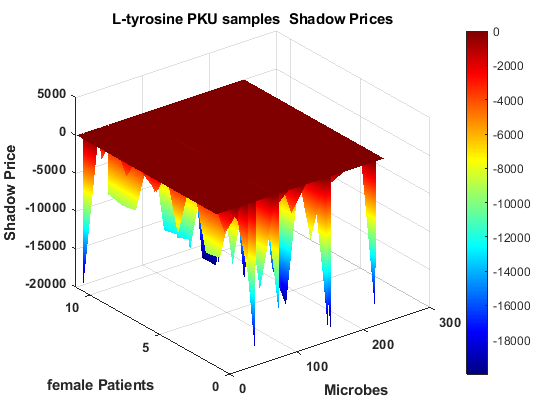

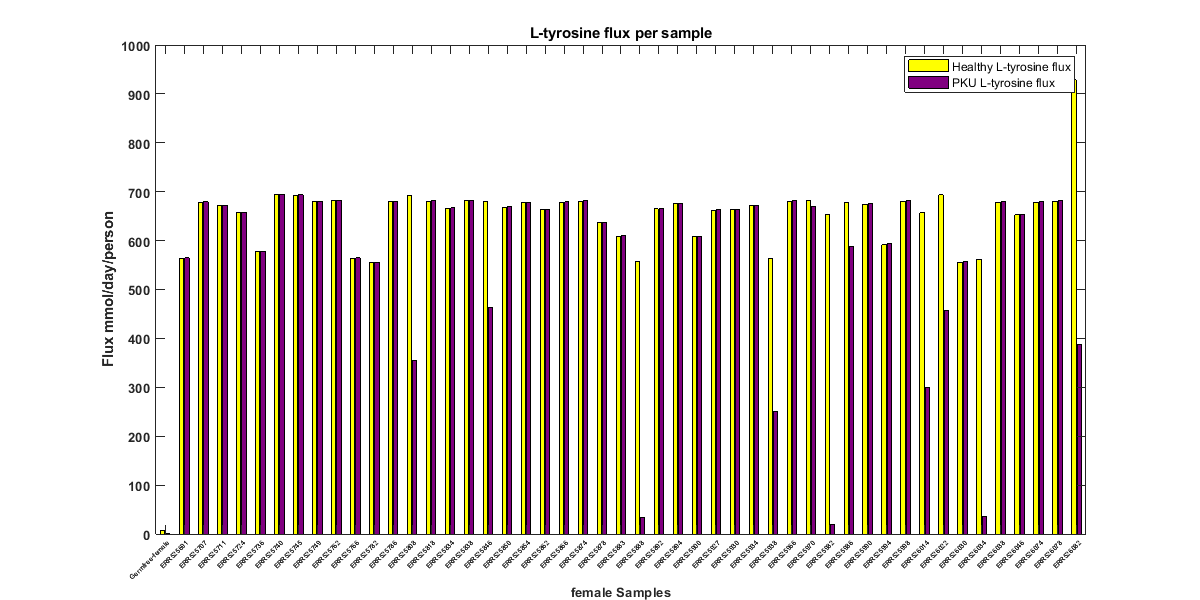

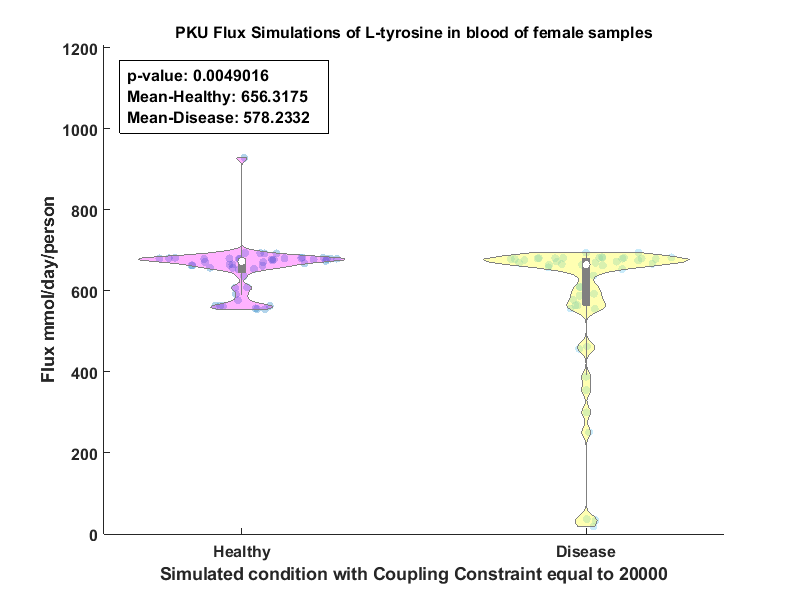

cd(Mdir)
compute = 1;
if compute
    %% ================================================================
    %
    % This section systematically analyzes metabolic biomarkers associated
    % with inherited metabolic disorders (IMDs) by identifying key gut
    % microbes contributing significantly to changes in biomarker fluxes.
    %
    % The analysis:
    %  1. Loads simulation results from host-microbiome metabolic models.
    %  2. Compares "Healthy" and "Disease" states for biomarker fluxes.
    %  3. Computes Z-scores and shadow prices to identify statistically
    %     significant outlier microbes.
    %  4. Determines microbes critically responsible for increasing or
    %     decreasing biomarker levels, revealing microbial contributions
    %     to metabolic disturbances.
    %  5. Outputs results as Excel summaries and generates detailed
    %     visualizations to facilitate biological interpretation.
    %
    % This comprehensive workflow assists investigators in pinpointing
    % microbial taxa as potential therapeutic targets or diagnostic
    % biomarkers in IMD-associated microbiome studies.
    % INPUTS (via dialog):
    % - Disease (e.g., 'PKU')
    % - Biomarker VMH ID (e.g., 'akg')
    % - Biomarker full name (e.g., 'Oxoglutaric acid')
    % - Sex ('female' or 'male')
    % - Coupling constraint (e.g., '400')
    % - Figure output resolution (DPI, e.g., 1000)
    %
    % OUTPUTS:
    % - Excel sheets of statistical summaries & microbial shadow prices
    % - High-resolution visualizations of results
    %
    % Author: M.Moghimi
    % Date: June 2025
    
    %% ================================================================
    
    clc
    
    clearvars -except Mdir Biomarkers
    
    close all
    warning off
    
    prompt = {'Disease','biomarker VMH id','biomaker full name','Sex','Coupling constraint','Figures output resolution'};
    tit = 'Initialize Host-Microbiome IEM biomarker analysis';
    
    options = struct;
    options.Resize = 'on';
    options.WindowStyle = 'normal';
    options.Interpreter = 'tex';
    lines = [1 20;1 20;1 20;1 20;1 20;1 20];
    def = {'PKU','tyr_L','L-tyrosine','female','20000','1000'};
    P1 = inputdlg(prompt,tit,lines,def,options);
    
    
    Disease = char(P1(1));
    biomarker(1) = cellstr(P1(2));
    biomarker(2) = cellstr(P1(3));
    sex = char(P1(4));
    CC = char(P1(5));
    outputResolution = double(string(P1(6)));
    
    %%
    C_dir = pwd;
    
    state = strcat(CC,'_',sex,'_',char(biomarker(1)));
    resultpath = fullfile(C_dir, 'saveDir', 'Stats', Disease, char(biomarker(1)));

    % Create all directories in the path if they do not exist
    if ~exist(resultpath, 'dir')
        mkdir(resultpath);
    end
    cd(resultpath)
    
    D_sheets = cellstr(sheetnames(strcat('flux_results_Disease',state,'.xlsx')));
    
    % Initialize a cell array to hold the data from each sheet
    D_data = cell(length(D_sheets), 1);
    
    % Loop through each sheet and read its data
    for i = 1:length(D_sheets)
        D_data{i} = readtable(strcat('flux_results_Disease',state,'.xlsx'), 'Sheet', D_sheets{i});
    end
    
    H_sheets = cellstr(sheetnames(strcat('flux_results_Healthy',state,'.xlsx')));
    
    % Initialize a cell array to hold the data from each sheet
    H_data = cell(length(H_sheets), 1);
    
    
    % Loop through each sheet and read its data
    for i = 1:length(H_sheets)
        H_data{i} = readtable(strcat('flux_results_Healthy',state,'.xlsx'), 'Sheet', H_sheets{i},'Range','A1','ReadVariableNames',false);
    end
    
    freq_Mic = table2cell(H_data{11}(:,1));
    
    if sum(cellfun(@(x,y) isequal(x,y), strrep(table2cell(H_data{9}(:,1)),'_Healthy',''), strrep(table2cell(D_data{9}(:,1)),'_Disease',''))) == length(table2cell(H_data{9}(:,1)))
        Samples = table2cell(D_data{9}(:,2));
        D_flux = table2cell(D_data{9}(:,4));
        H_flux = table2cell(H_data{9}(:,4));
        
        M_D_flux = table2cell(D_data{10}(:,4));
        M_H_flux = table2cell(H_data{10}(:,4));
        
        Increased_ID = find(((cell2mat(D_flux)-cell2mat(H_flux))./cell2mat(H_flux))>0.01);
        Decreased_ID = find(((cell2mat(D_flux)-cell2mat(H_flux))./cell2mat(H_flux))<-0.01);
        
    else
        error('The samples do not match')
    end
    
    if isempty(Increased_ID)
        
        mode = 1;
        
    elseif isempty(Decreased_ID)
        
        mode = 2;
    else
        
        mode = 3;
        
    end
    %%
    
    switch mode
        
        case 1
            %%
            cd(C_dir)
            C = [cell2mat(H_flux),cell2mat(D_flux)];
            
            [~, p_value] = ttest2(C(:,1), C(:,2));
            % fdr = mfdr1(p_value);
            color = {'g', 'b', 'r', 'y', 'm','c'}; % Define colors for each violin
            color_ID1 =randi(5,1,1);
            colors(1) = color(color_ID1);color(color_ID1) = [];
            colors(2) = color(randi(4,1,1));
            
            figure()
            h = violinplot(C);
            xt = get(gca, 'XTick');set(gca,'XTick',xt,'XTickLabel',{strcat('Healthy') strcat('Disease')})
            ax = gca;
            for i = 1:numel(h)
                set(h(i).ViolinPlot, 'FaceColor', colors{i});
            end
            xlabel(['Simulated condition with Coupling Constraint equal to' ' ' CC]);
            ylabel('Flux mmol/day/person');
            ylim([0,1.3*max(C(:,1))])
            ax.XAxis.FontSize = 12; ax.YAxis.FontSize = 12;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            title([Disease ' ' 'Flux Simulations of' ' ' char(biomarker(2)) ' '  'in blood of' ' ' sex ' ' 'samples']);
            ax.Title.FontSize = 12;
            mean_value_Healthy = mean(C(:,1));
            mean_value_Disease = mean(C(:,2));
            
            % Calculate the mean
            set(gcf, 'Position', [100, 100, 800, 600]);
            % Create a legend text box
            legend_text = {['p-value: ' num2str(p_value)],['Mean-Healthy: ' num2str(mean_value_Healthy)],['Mean-Disease: ' num2str(mean_value_Disease)]};
            annotation('textbox', [0.15, 0.6, 0.3, 0.3], 'String', legend_text, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'FontSize', 12,'FontWeight', 'bold');
            set(gcf, 'Name', [char(biomarker(1)) '_fluxes_Violinplot_' CC '_' sex], 'NumberTitle', 'off');
            
            
            %%
            cd(resultpath)
            
            figure;
            
            % Extract data from H_data and D_data
            H_values = cell2mat(table2cell(H_data{9}(:, 4)));
            D_values = cell2mat(table2cell(D_data{9}(:, 4)));
            Germfreee_H_values = cell2mat(table2cell(H_data{8}(:, 2)));
            Germfreee_D_values = cell2mat(table2cell(D_data{8}(:, 2)));
            
            
            % Combine H_data and D_data values into a matrix
            % Each row represents a different sample, and each column represents H_data and D_data
            combined_data = [[Germfreee_H_values;H_values], [Germfreee_D_values;D_values]];
            writecell([[{'Samples'},{'Healthy Flux'},{[Disease ' ' 'Flux']}];[[{'Germfree-female'};Samples],num2cell(combined_data)]], 'Samples_Info.xlsx','Sheet', ['flux_',state]);
            cd(C_dir)
            % Create a grouped bar plot
            Rxns_flux = bar(combined_data, 'grouped');
            
            % Set colors for each group (yellow for H_data and purple for D_data)
            Rxns_flux(1).FaceColor = [1, 1, 0];    % Yellow for H_data
            Rxns_flux(2).FaceColor = [0.5, 0, 0.5]; % Purple for D_data
            
            % Set axis labels and other figure properties
            set(gca, 'XTick', 1:length(Samples)+1, 'XTickLabel', [{'Germfree-female'};Samples], 'XTickLabelRotation', 45);
            set(gcf, 'Position', [100, 100, 1200, 600]);
            title([char(biomarker(2)),' ','flux per sample']);
            ax = gca; ax.XAxis.FontSize = 5;
            xlabel(strcat(sex,' Samples'), 'FontSize', 10)
            ylabel('Flux mmol/day/person');
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            % Add legend to indicate which color represents which dataset
            legend({['Healthy',' ',char(biomarker(2)),' ','flux'], [Disease,' ',char(biomarker(2)),' ','flux']}, 'Location', 'northeast');
            set(gcf, 'Name', [char(biomarker(1)) '_fluxes_' CC '_' sex], 'NumberTitle', 'off');
            
            
            SP_path = [C_dir filesep 'saveDir' filesep 'microbeShadowPrices' filesep Disease filesep char(biomarker(1))];
            cd(SP_path)
            sp_state = [CC,'_',sex,'_DM_',char(biomarker(1)),'[bc].csv'];
            H_SP = readtable(['Healthy',sp_state]);
            D_SP = readtable(['Disease',sp_state]);
            
            all_microbes(:,1) = freq_Mic; all_microbes(:,2) = {'0'};
            Microbes = freq_Mic;
            H = cellfun(@(x) isnan(x), table2cell(H_SP(:,2:end)), 'UniformOutput', false);
            H = find(cell2mat(H)==1);
            D = cellfun(@(x) isnan(x), table2cell(D_SP(:,2:end)), 'UniformOutput', false);
            D = find(cell2mat(D)==1);
            
            R = D_SP.Properties.VariableDescriptions;R(1) = [];
            [~,I1] = ismember(freq_Mic,R);
            
            
            H_SP = cell2mat(table2cell(H_SP(:,2:end)));
            H_SP = H_SP(:,I1);
            D_SP = cell2mat(table2cell(D_SP(:,2:end)));
            D_SP = D_SP(:,I1) ;
            SP_Substraction = D_SP - H_SP;
            
            abun_corr = table2array(D_data{11}(:,2));
            M_abun_corr = table2array(D_data{11}(:,1));
            abun_corr(isnan(abun_corr)) = 0;
            I_M_abun_corr = M_abun_corr(abun_corr>0);
            D_M_abun_corr = M_abun_corr(abun_corr<0);
            abun_corr = num2cell(abun_corr);
            
            d_score = zeros(length(Microbes),1);
            d_Microbes = zeros(length(Microbes),2);
            
            for i = 1:length(Decreased_ID)
                
                SP = SP_Substraction(Decreased_ID(i),:);
                d_SP =SP(~isnan(SP));
                d_microbe = Microbes(~isnan(SP));
                d_score = d_score +  matches(Microbes,d_microbe);
                d_Microbes(~isnan(SP),1) = d_Microbes(~isnan(SP),1) + d_SP';
                d_Microbes(~isnan(SP),2) = d_Microbes(~isnan(SP),2) + 1;
                
            end
            
            d_Microbes = d_Microbes(:,1)./d_Microbes(:,2); d_Microbes(isnan(d_Microbes)) = 0;
            [~,inx] = ismember(table2cell(D_data{11}(:,1)),Microbes);
            d_all_microbes = all_microbes;
            d_all_microbes(:,2) = num2cell(d_score/length(Decreased_ID));
            d_all_microbes(:,3) = num2cell(d_Microbes);
            d_all_microbes(:,4) = num2cell(zeros(length(Microbes),1));
            d_all_microbes(inx,4) = abun_corr;
            
            
            D_SP2 = D_SP;
            H_SP2 = H_SP;
            
            D_SP(isnan(D_SP)) = 0;
            H_SP(isnan(H_SP)) = 0;
            
            for i = 1:length(Decreased_ID)
                
                [a1,b1] = min(D_SP(Decreased_ID(i),:));
                
                [a2,b2] = max(D_SP(Decreased_ID(i),:));
                
                
            end
            
            
      
            [n_samples,numb_Microbes] = size(D_SP);
            [X, Y] = meshgrid(1:numb_Microbes, 1:length(Decreased_ID));  % X for microbes, Y for patients
            figure;
            surf(X, Y, D_SP(Decreased_ID,:));
            xlabel('Microbes');
            ylabel([sex,' ','Patients']);
            zlabel('Shadow Price');
            title([char(biomarker(2)),' ',Disease,' ','samples  Shadow Prices']);
            colormap('jet');
            colorbar;shading interp;   % Interpolates shading for smoother surface
            lighting gouraud;
            material([1, 0.7, 0.3]); % Applies smooth lighting
            camlight('headlight');
            ax = gca;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            ax.ZAxis.FontWeight = 'bold';
            set(gcf, 'Name', [char(biomarker(2)) '_fluxes_' CC '_' sex], 'NumberTitle', 'off');
            set(gcf, 'Name', ['SP_Decreased_' char(biomarker(1)) '_' Disease '_samples_' CC '_' sex], 'NumberTitle', 'off');
            
            
            global_mean = mean(D_SP2(~isnan(D_SP2)));
            global_std = std(D_SP2(~isnan(D_SP2)));
            z_scores = (D_SP - global_mean) ./ global_std;
            A = (sum((z_scores)<-1));
            
            figure;
            Rxns_flux = barh(A(A>0));
            Rxns_flux.FaceColor = 'flat';
            Rxns_flux.CData = rand(length(find(A>0)), 3);
            set(gca, 'YTick', 1:length(Microbes(find(A>0))), 'YTickLabel', strrep(string(Microbes(find(A>0))),'_','-'), 'YTickLabelRotation', 0,'FontSize',5)
            set(gcf, 'Position', [100, 100, 600, 1200]);
            title(['Microbes with strongly negative shadow Price in All' ' ' Disease ' ' 'samples'],'FontSize', 10);
            xlabel(['Count of appearances as key contributing microbes for',' ',char(biomarker(2)),' ','production in',' ',sex,' ','samples']);
            ax = gca;
            ax.XAxis.FontSize = 10;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            set(gcf, 'Name', ['SNSP_' char(biomarker(1)) '_' CC '_' sex], 'NumberTitle', 'off');
            
            
            G = Microbes(find(A>0));
            [inx1,inx2] = ismember(G,table2cell(D_data{11}(:,1)));
            Y = zeros(length(G),1);
            inx2(inx2==0) = [];
            Y(inx1) = cell2mat(table2cell(D_data{11}(inx2,2))); Y = round(Y,2);
            
            Outlie_Microbes = sortrows([G,num2cell(A(A>0)'),num2cell(Y)],-2);
            a1 = sum(D_SP<=0);
            a2 = find(a1==n_samples);
            a3 = sortrows( [sum(D_SP(:,a2)<0)',mean(D_SP(:,a2))',a2'],-1);
            Q = sortrows(a3,-1);
            mkdir([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2))])
            mkdir([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC])
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            
            allFigures = findall(0, 'Type', 'figure');
            
            % Filter to include only figures with a "Number" property (regular plots)
            plotFigures = allFigures(arrayfun(@(f) ~isempty(f.Number), allFigures));
            % outputResolution = 1200;
            
            for i = 1:length(plotFigures)
                fig = plotFigures(i);  % Get the current figure
                
                % Set figure size
                fig.Units = 'pixels';
                % Turn off anti-aliasing for crisp lines (optional)
                set(fig, 'GraphicsSmoothing', 'off');
                
                % Save the figure with high resolution
                fileName = [fig.Name '.png'];  % File name based on figure name
                print(fig, fileName, '-dpng', ['-r' num2str(outputResolution)]);  % Save PNG
            end
            
            
            close all
            
            cd(strcat(C_dir,filesep,'microbiomeDir'));
            abun = readtable(['microbiomeDir_',sex,'.csv']);
            abun2 = table2cell(abun);
            [~,I2]=ismember(freq_Mic,abun2(:,1));
            abun = abun(I2,:);
            abun2 = abun2(I2,:);
            
            
            ind = [];
            zero_down_abun = [];
            for i = 1:length(Outlie_Microbes(:,1))
                
                M = find(ismember(freq_Mic,Outlie_Microbes(i,1)));
                outlie_sample = find(z_scores(:,M)<-1);
                zero_down_abun = [zero_down_abun;sum(cell2mat(abun2(M,Decreased_ID+1))==0)];
                ind = [ind,(sum(ismember(outlie_sample,Decreased_ID))+zero_down_abun(i))/length(Decreased_ID)];
                
            end
            ind = round(ind,2);
            Outlie_Microbes = [Outlie_Microbes,num2cell(ind'),num2cell(zero_down_abun)];
            Outlie_Microbes2(:,1:2) = Outlie_Microbes(:,1:2);Outlie_Microbes2(:,3) = num2cell(zero_down_abun); Outlie_Microbes2(:,4) = Outlie_Microbes(:,3); Outlie_Microbes2(:,5) = num2cell(ind');
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            Outlie_Microbes2 = [[{'Microbes'},{'Occurrence'},{'Other Decreased samples with 0 abundance'},{'abundance-flux correlation'},{'SNSP fraction in decreased samples'}];Outlie_Microbes2];
            writecell(Outlie_Microbes2, ['SNSP_Microbes_',state,'.xlsx'],'Range', 'A2');
            [~,inx4] = ismember(Outlie_Microbes(:,1),freq_Mic(:,1));
            top10 = inx4;
            
            if length(zero_down_abun)>10
                remain1 = find((ind(1:10)~=0));
            else
                remain1 = find((ind(1:length(ind))~=0));
            end
            
            Top_microbes = top10(remain1);
            D_abun_corr = table2cell(D_data{11});
            H_abun_corr = table2cell(H_data{11});
            samples_mean2 = [];
            samples_abun_corr = [];
            
            Increased_ID = 1:length(Samples); Increased_ID(Decreased_ID) = [];
            for i = 1:length(Top_microbes)
                
                A = abun(Top_microbes(i),Decreased_ID+1);
                Mic = ((freq_Mic(Top_microbes(i))));
                filename = strcat('Top_M_examin',CC,'_',sex,'.xlsx'); sheetname = string(i);
                
                writecell([Mic;{'Mean Abundance'}],filename,'Sheet',sheetname,'Range','A5')
                writecell([{'Samples'};{'Abundances'}],filename,'Sheet',sheetname,'Range','A2')
                writecell([A.Properties.VariableNames;abun2(Top_microbes(i),Decreased_ID+1)],filename,'Sheet',sheetname,'Range','B2')
                
                mean_down =  mean(cell2mat(abun2(Top_microbes(i),Decreased_ID+1)));
                mean_high =  mean(cell2mat(abun2(Top_microbes(i),Increased_ID+1)));
                samples_mean = [[{'Decrease_samples'},{'Increase or unchanged samples'}];num2cell([mean_down,mean_high])];
                writecell(samples_mean,filename,'Sheet',sheetname,'Range','B5');
                
                abun_corr_DID = find((ismember(D_abun_corr(:,1),Mic)));
                abun_corr_HID = find((ismember(H_abun_corr(:,1),Mic)));
                
                writecell([{'Healthy abun corr'},{'Disease abun corr'}],filename,'Sheet',sheetname,'Range','B8')
                
                writecell([H_abun_corr(abun_corr_HID,2),D_abun_corr(abun_corr_DID,2)],filename,'Sheet',sheetname,'Range','B9')
                samples_mean2 = [samples_mean2;[mean_down,mean_high]];
                samples_abun_corr = [samples_abun_corr;[H_abun_corr(abun_corr_HID,2),D_abun_corr(abun_corr_DID,2)]];
                
                
            end
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            abun_compar = [[{'Microbes'};all_microbes(Top_microbes)],[[{'Decreased_samples_Mean Abundance'},{'Other_samples_Mean Abundance'}];num2cell(samples_mean2)]];
            writecell(abun_compar, strcat('SNSP_Microbes',CC,'_',sex,'2.xlsx'),'Sheet', 'abun_compar');
            abuncorr_compar = [[{'Microbes'};all_microbes(Top_microbes)],[[{'Healthy abundanc/flux corr'},{'Disease abundanc/flux corr'}];samples_abun_corr]];
            writecell(abuncorr_compar, strcat('SNSP_Microbes',CC,'_',sex,'2.xlsx'),'Sheet', 'abuncorr_compar');
            
        case 2
            %%
            cd(C_dir)
            C = [cell2mat(H_flux),cell2mat(D_flux)];
            
            [~, p_value] = ttest2(C(:,1), C(:,2));
            
            color = {'g', 'b', 'r', 'y', 'm','c'}; % Define colors for each violin
            color_ID1 =randi(5,1,1);
            colors(1) = color(color_ID1);color(color_ID1) = [];
            colors(2) = color(randi(4,1,1));
            
            figure()
            h = violinplot(C);
            xt = get(gca, 'XTick');set(gca,'XTick',xt,'XTickLabel',{strcat('Healthy') strcat('Disease')})
            ax = gca;
            for i = 1:numel(h)
                set(h(i).ViolinPlot, 'FaceColor', colors{i});
            end
            xlabel(['Simulated condition with Coupling Constraint equal to' ' ' CC]);
            ylabel('Flux mmol/day/person');
            ax.XAxis.FontSize = 12; ax.YAxis.FontSize = 12;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            title([Disease ' ' 'Flux Simulations of' ' ' char(biomarker(2)) ' '  'in blood of' ' ' sex ' ' 'samples']);
            ax.Title.FontSize = 12;
            mean_value_Healthy = mean(C(:,1));
            mean_value_Disease = mean(C(:,2));
            
            % Calculate the mean
            set(gcf, 'Position', [100, 100, 800, 600]);
            % Create a legend text box
            legend_text = {['p-value: ' num2str(p_value)],['Mean-Healthy: ' num2str(mean_value_Healthy)],['Mean-Disease: ' num2str(mean_value_Disease)]};
            annotation('textbox', [0.15, 0.6, 0.3, 0.3], 'String', legend_text, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'FontSize', 12,'FontWeight', 'bold');
            set(gcf, 'Name', [char(biomarker(1)) '_fluxes_Violinplot_' CC '_' sex], 'NumberTitle', 'off');
            
            %%
            
            
            % [~,A2] = ismember(Samples(Increased_ID),samp_data2(:,2));
            % samp_data2(A2,:);
            cd(resultpath)
            % writecell([samp_data.Properties.VariableDescriptions;samp_data2(A2,:)], 'Samples_Info.xlsx','Sheet', 'females_Samples_Info');
            
            figure;
            
            % Extract data from H_data and D_data
            H_values = cell2mat(table2cell(H_data{9}(:, 4)));
            D_values = cell2mat(table2cell(D_data{9}(:, 4)));
            Germfreee_H_values = cell2mat(table2cell(H_data{8}(:, 2)));
            Germfreee_D_values = cell2mat(table2cell(D_data{8}(:, 2)));
            
            
            % Combine H_data and D_data values into a matrix
            % Each row represents a different sample, and each column represents H_data and D_data
            combined_data = [[Germfreee_H_values;H_values], [Germfreee_D_values;D_values]];
            writecell([[{'Samples'},{'Healthy Flux'},{[Disease ' ' 'Flux']}];[[{'Germfree-female'};Samples],num2cell(combined_data)]], 'Samples_Info.xlsx','Sheet', ['flux_',state]);
            cd(C_dir)
            % Create a grouped bar plot
            Rxns_flux = bar(combined_data, 'grouped');
            
            % Set colors for each group (yellow for H_data and purple for D_data)
            Rxns_flux(1).FaceColor = [0, 1, 0];    % Green for H_data
            Rxns_flux(2).FaceColor = [1, 0, 0];    % Red for D_data
            
            % Set axis labels and other figure properties
            set(gca, 'XTick', 1:length(Samples)+1, 'XTickLabel', [{'Germfree-female'};Samples], 'XTickLabelRotation', 45);
            set(gcf, 'Position', [100, 100, 1200, 600]);
            title([char(biomarker(2)),' ','flux per sample']);
            ax = gca; ax.XAxis.FontSize = 5;
            xlabel('Samples', 'FontSize', 10)
            ylabel('Flux mmol/day/person');
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            % Add legend to indicate which color represents which dataset
            legend({['Healthy',' ',char(biomarker(2)),' ','flux'], [Disease,' ',char(biomarker(2)),' ','flux']}, 'Location', 'northeast');
            set(gcf, 'Name', [char(biomarker(1)) '_fluxes_' CC '_' sex], 'NumberTitle', 'off');
            
            
            
            SP_path = [C_dir filesep 'saveDir' filesep 'microbeShadowPrices' filesep Disease filesep char(biomarker(1))];
            cd(SP_path)
            sp_state = [CC,'_',sex,'_DM_',char(biomarker(1)),'[bc].csv'];
            H_SP = readtable(['Healthy',sp_state]);
            D_SP = readtable(['Disease',sp_state]);
            
            all_microbes(:,1) = freq_Mic; all_microbes(:,2) = {'0'};
            Microbes = freq_Mic;
            H = cellfun(@(x) isnan(x), table2cell(H_SP(:,2:end)), 'UniformOutput', false);
            H = find(cell2mat(H)==1);
            D = cellfun(@(x) isnan(x), table2cell(D_SP(:,2:end)), 'UniformOutput', false);
            D = find(cell2mat(D)==1);
            
            R = D_SP.Properties.VariableDescriptions;R(1) = [];
            [~,I1] = ismember(freq_Mic,R);
            
            
            H_SP = cell2mat(table2cell(H_SP(:,2:end)));
            H_SP = H_SP(:,I1);
            D_SP = cell2mat(table2cell(D_SP(:,2:end)));
            D_SP = D_SP(:,I1) ;
            SP_Substraction = D_SP - H_SP;
            
            abun_corr = table2array(D_data{11}(:,2));
            M_abun_corr = table2array(D_data{11}(:,1));
            abun_corr(isnan(abun_corr)) = 0;
            I_M_abun_corr = M_abun_corr(abun_corr>0);
            D_M_abun_corr = M_abun_corr(abun_corr<0);
            abun_corr = num2cell(abun_corr);
            
            d_score = zeros(length(Microbes),1);
            d_Microbes = zeros(length(Microbes),2);
            
            for i = 1:length(Increased_ID)
                
                SP = SP_Substraction(Increased_ID(i),:);
                d_SP =SP(~isnan(SP));
                d_microbe = Microbes(~isnan(SP));
                d_score = d_score +  matches(Microbes,d_microbe);
                d_Microbes(~isnan(SP),1) = d_Microbes(~isnan(SP),1) + d_SP';
                d_Microbes(~isnan(SP),2) = d_Microbes(~isnan(SP),2) + 1;
                
            end
            
            d_Microbes = d_Microbes(:,1)./d_Microbes(:,2); d_Microbes(isnan(d_Microbes)) = 0;
            [~,inx] = ismember(table2cell(D_data{11}(:,1)),Microbes);
            d_all_microbes = all_microbes;
            d_all_microbes(:,2) = num2cell(d_score/length(Increased_ID));
            d_all_microbes(:,3) = num2cell(d_Microbes);
            d_all_microbes(:,4) = num2cell(zeros(length(Microbes),1));
            d_all_microbes(inx,4) = abun_corr;
            
            D_SP2 = D_SP;
            H_SP2 = H_SP;
            
            D_SP(isnan(D_SP)) = 0;
            H_SP(isnan(H_SP)) = 0;
            
            for i = 1:length(Increased_ID)
                
                [a1,b1] = min(D_SP(Increased_ID(i),:));
                
                [a2,b2] = max(D_SP(Increased_ID(i),:));
                
                
            end
            
            [n_samples,numb_Microbes] = size(D_SP);
            
            [X, Y] = meshgrid(1:numb_Microbes, 1:length(Increased_ID));  % X for microbes, Y for patients
            figure;
            surf(X, Y, D_SP(Increased_ID,:));
            xlabel('Microbes');
            ylabel('Patients');
            zlabel('Shadow Price');
            title([char(biomarker(2)),' ',Disease,' ','samples  Shadow Prices']);
            colormap('jet');
            colorbar;shading interp;   % Interpolates shading for smoother surface
            lighting gouraud;
            material([1, 0.7, 0.3]); % Applies smooth lighting
            camlight('headlight');
            ax = gca;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            ax.ZAxis.FontWeight = 'bold';
            ax.ZAxis.FontWeight = 'bold';
            set(gcf, 'Name', [char(biomarker(2)) '_fluxes_' CC '_' sex], 'NumberTitle', 'off');
            set(gcf, 'Name', ['SP_Decreased_' char(biomarker(1)) '_' Disease '_samples_' CC '_' sex], 'NumberTitle', 'off');
            
            
            global_mean = mean(D_SP2(~isnan(D_SP2)));
            global_std = std(D_SP2(~isnan(D_SP2)));
            z_scores = (D_SP - global_mean) ./ global_std;
            A = (sum((z_scores)<-1));
            
            figure;
            Rxns_flux = barh(A(A>0));
            Rxns_flux.FaceColor = 'flat';
            Rxns_flux.CData = rand(length(find(A>0)), 3);
            set(gca, 'YTick', 1:length(Microbes(find(A>0))), 'YTickLabel', strrep(string(Microbes(find(A>0))),'_','-'), 'YTickLabelRotation', 0,'FontSize',5)
            set(gcf, 'Position', [100, 100, 600, 1200]);
            title(['Microbes with strongly negative shadow Price in All' ' ' Disease ' ' 'samples'],'FontSize', 10);
            xlabel(['Count of appearances as key contributing microbes for',' ',char(biomarker(2)),' ','production in',' ',sex,' ','samples']);
            ax = gca;
            ax.XAxis.FontSize = 10;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            set(gcf, 'Name', ['SNSP_' char(biomarker(1)) '_' CC '_' sex], 'NumberTitle', 'off');
            
            G = Microbes(find(A>0));
            [inx1,inx2] = ismember(G,table2cell(D_data{11}(:,1)));
            Y = zeros(length(G),1);
            inx2(inx2==0) = [];
            Y(inx1) = cell2mat(table2cell(D_data{11}(inx2,2))); Y = round(Y,2);
            
            Outlie_Microbes = sortrows([G,num2cell(A(A>0)'),num2cell(Y)],-2);
            
            a1 = sum(D_SP>=0);
            a2 = find(a1==48);
            a3 = sortrows( [sum(D_SP(:,a2)>0)',mean(D_SP(:,a2))',a2'],-1);
            Q = sortrows(a3,-1);
            mkdir([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2))])
            mkdir([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC])
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            
            allFigures = findall(0, 'Type', 'figure');
            
            % Filter to include only figures with a "Number" property (regular plots)
            plotFigures = allFigures(arrayfun(@(f) ~isempty(f.Number), allFigures));
            
            % outputResolution = 1200;  % Set very high resolution (DPI)
            
            for i = length(plotFigures)
                fig = plotFigures(i);  % Get the current figure
                
                % Set figure size
                fig.Units = 'pixels';
                
                % Turn off anti-aliasing for crisp lines (optional)
                set(fig, 'GraphicsSmoothing', 'off');
                
                % Save the figure with high resolution
                fileName = [fig.Name '.png'];  % File name based on figure name
                print(fig, fileName, '-dpng', ['-r' num2str(outputResolution)]);  % Save PNG
            end
            
            
            close all
            
            cd(strcat(C_dir,filesep,'microbiomeDir'));
            abun = readtable('microbiomeDir_female.csv');
            abun2 = table2cell(abun);
            [~,I2]=ismember(freq_Mic,abun2(:,1));
            abun = abun(I2,:);
            abun2 = abun2(I2,:);
            
            
            D_abun_corr = table2cell(D_data{11});
            H_abun_corr = table2cell(H_data{11});
            Outlie_Microbes = Outlie_Microbes(ismember(Outlie_Microbes(:,1),H_abun_corr(:,1)),:);
            ind = [];
            zero_down_abun = [];
            for i = 1:length(Outlie_Microbes(:,1))
                
                M = find(ismember(freq_Mic,Outlie_Microbes(i,1)));
                outlie_sample = find(z_scores(:,M)<-1);
                
                zero_down_abun = [zero_down_abun;sum(cell2mat(abun2(M,Increased_ID+1))==0)];
                ind = [ind,(sum(ismember(outlie_sample,Increased_ID))+zero_down_abun(i))/length(Increased_ID)];
                
                
            end
            ind = round(ind,2);
            Outlie_Microbes = [Outlie_Microbes,num2cell(ind'),num2cell(zero_down_abun)];
            Outlie_Microbes2(:,1:2) = Outlie_Microbes(:,1:2);Outlie_Microbes2(:,3) = num2cell(zero_down_abun); Outlie_Microbes2(:,4) = Outlie_Microbes(:,3); Outlie_Microbes2(:,5) = num2cell(ind');
            cd(strcat(C_dir,filesep,'saveDir',filesep,'microbeShadowPrices'));
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            Outlie_Microbes2 = [[{'Microbes'},{'Occurrence'},{'Remaining samples with 0 abundance'},{'abundance-flux correlation'},{'SNSP fraction in decreased samples'}];Outlie_Microbes2];
            writecell(Outlie_Microbes2, ['SNSP_Microbes_',state,'.xlsx'],'Range', 'A2');
            
            [~,inx4] = ismember(Outlie_Microbes(:,1),freq_Mic(:,1));
            top10 = inx4;
            
            if length(zero_down_abun)>10
                remain1 = find((ind(1:10)~=0));
            else
                remain1 = find((ind(1:length(ind))~=0));
            end
            
            
            Top_microbes = top10(remain1);
            samples_mean2 = [];
            samples_abun_corr = [];
            for i = 1:length(Top_microbes)
                
                A = abun(Top_microbes(i),Increased_ID+1);
                Mic = ((all_microbes(Top_microbes(i))));
                filename = strcat('Top_M_examin',CC,'_',sex,'.xlsx'); sheetname = string(i);
                
                writecell([Mic;{'Mean Abundance'}],filename,'Sheet',sheetname,'Range','A5')
                writecell([{'Samples'};{'Abundances'}],filename,'Sheet',sheetname,'Range','A2')
                writecell([A.Properties.VariableNames;abun2(Top_microbes(i),Decreased_ID+1)],filename,'Sheet',sheetname,'Range','B2')
                mean_down =  mean(cell2mat(abun2(Top_microbes(i),Decreased_ID+1)));
                mean_high =  mean(cell2mat(abun2(Top_microbes(i),Increased_ID+1)));
                samples_mean = [[{'Decrease_samples'},{'Increase_samples'}];num2cell([mean_down,mean_high])];
                writecell(samples_mean,filename,'Sheet',sheetname,'Range','B5');
                
                abun_corr_DID = find((ismember(D_abun_corr(:,1),Mic)));
                abun_corr_HID = find((ismember(H_abun_corr(:,1),Mic)));
                
                writecell([{'Healthy abun corr'},{'Disease abun corr'}],filename,'Sheet',sheetname,'Range','B8')
                
                if ~ isempty(abun_corr_DID | abun_corr_HID)
                    writecell([H_abun_corr(abun_corr_HID,2),D_abun_corr(abun_corr_DID,2)],filename,'Sheet',sheetname,'Range','B9')
                end
                samples_mean2 = [samples_mean2;[mean_down,mean_high]];
                samples_abun_corr = [samples_abun_corr;[H_abun_corr(abun_corr_HID,2),D_abun_corr(abun_corr_DID,2)]];
                
                
            end
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            abun_compar = [[{'Microbes'};all_microbes(Top_microbes)],[[{'Decreased_samples_Mean Abundance'},{'Increased_samples_Mean Abundance'}];num2cell(samples_mean2)]];
            writecell(abun_compar, strcat('SNSP_Microbes',CC,'_',sex,'2.xlsx'),'Sheet', 'abun_compar');
            abuncorr_compar = [[{'Microbes'};all_microbes(Top_microbes)],[[{'Healthy abundanc/flux corr'},{'Disease abundanc/flux corr'}];samples_abun_corr]];
            writecell(abuncorr_compar, strcat('SNSP_Microbes',CC,'_',sex,'2.xlsx'),'Sheet', 'abuncorr_compar');
            
        case 3
            %%
            cd(C_dir)
            C = [cell2mat(H_flux),cell2mat(D_flux)];
            
            [~, p_value] = ttest2(C(:,1), C(:,2));
            
            color = {'g', 'b', 'r', 'y', 'm','c'}; % Define colors for each violin
            color_ID1 =randi(5,1,1);
            colors(1) = color(color_ID1);color(color_ID1) = [];
            colors(2) = color(randi(4,1,1));
            
            figure()
            h = violinplot(C);
            xt = get(gca, 'XTick');set(gca,'XTick',xt,'XTickLabel',{strcat('Healthy') strcat('Disease')})
            ax = gca;
            for i = 1:numel(h)
                set(h(i).ViolinPlot, 'FaceColor', colors{i});
            end
            xlabel(['Simulated condition with Coupling Constraint equal to' ' ' CC]);
            ylabel('Flux mmol/day/person');
            ylim([0,1.3*max(C(:,1))])
            ax.XAxis.FontSize = 12; ax.YAxis.FontSize = 12;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            title([Disease ' ' 'Flux Simulations of' ' ' char(biomarker(2)) ' '  'in blood of' ' ' sex ' ' 'samples']);
            ax.Title.FontSize = 12;
            mean_value_Healthy = mean(C(:,1));
            mean_value_Disease = mean(C(:,2));
            
            set(gcf, 'Position', [100, 100, 800, 600]);
            % Create a legend text box
            legend_text = {['p-value: ' num2str(p_value)],['Mean-Healthy: ' num2str(mean_value_Healthy)],['Mean-Disease: ' num2str(mean_value_Disease)]};
            annotation('textbox', [0.15, 0.6, 0.3, 0.3], 'String', legend_text, 'FitBoxToText', 'on', 'BackgroundColor', 'w', 'FontSize', 12,'FontWeight', 'bold');
            set(gcf, 'Name', [char(biomarker(1)) '_fluxes_Violinplot_' CC '_' sex], 'NumberTitle', 'off');
             
            
            %%
            
            % [~,A2] = ismember(Samples,samp_data2(:,2));
            % samp_data2(A2,:)
            cd(resultpath)
            % writecell([samp_data.Properties.VariableDescriptions;samp_data2(A2,:)], 'Samples_Info.xlsx','Sheet', 'females_Samples_Info');
            figure;
            
            % Extract data from H_data and D_data
            H_values = cell2mat(table2cell(H_data{9}(:, 4)));
            D_values = cell2mat(table2cell(D_data{9}(:, 4)));
            Germfreee_H_values = cell2mat(table2cell(H_data{8}(:, 2)));
            Germfreee_D_values = cell2mat(table2cell(D_data{8}(:, 2)));
            
            % Combine H_data and D_data values into a matrix
            % Each row represents a different sample, and each column represents H_data and D_data
            combined_data = [[Germfreee_H_values;H_values], [Germfreee_D_values;D_values]];
            writecell([[{'Samples'},{'Healthy Flux'},{[Disease ' ' 'Flux']}];[[{'Germfree-female'};Samples],num2cell(combined_data)]], 'Samples_Info.xlsx','Sheet', ['flux_',state]);
            % Create a grouped bar plot
            cd(C_dir)
            Rxns_flux = bar(combined_data, 'grouped');
            
            % Set colors for each group (yellow for H_data and purple for D_data)
            Rxns_flux(1).FaceColor = [1, 1, 0];    % Yellow for H_data
            Rxns_flux(2).FaceColor = [0.5, 0, 0.5]; % Purple for D_data
            
            %%
            % Set axis labels and other figure properties
            set(gca, 'XTick', 1:length(Samples)+1, 'XTickLabel', [{'Germfree-female'};Samples], 'XTickLabelRotation', 45);
            set(gcf, 'Position', [100, 100, 1200, 600]);
            title([char(biomarker(2)),' ','flux per sample']);
            ax = gca; ax.XAxis.FontSize = 5;
            xlabel(strcat(sex,' Samples'), 'FontSize', 10)
            ylabel('Flux mmol/day/person');
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            % Add legend to indicate which color represents which dataset
            legend({['Healthy',' ',char(biomarker(2)),' ','flux'], [Disease,' ',char(biomarker(2)),' ','flux']}, 'Location', 'northeast');
            set(gcf, 'Name', [char(biomarker(1)) '_fluxes_' CC '_' sex], 'NumberTitle', 'off');
            %%
            figure;
            Rxns_flux = bar(cell2mat(D_flux)-cell2mat(H_flux));
            Rxns_flux.FaceColor = 'flat';
            Rxns_flux.CData = rand(length(Samples), 3);
            set(gca, 'XTick', 1:length(Samples), 'XTickLabel', Samples, 'XTickLabelRotation', 45)
            set(gcf, 'Position', [100, 100, 1200, 600]);
            title([char(biomarker(2)),' substraction : Disease - Healthy']);
            xlabel(strcat(sex,' Samples'));
            ylabel('Substractions')
            set(gcf, 'Name', [char(biomarker(1)) '_Substraction_' CC '_' sex], 'NumberTitle', 'off');
            
            %%
            figure;
            Rxns_flux = bar(cell2mat(D_flux(Increased_ID))-cell2mat(H_flux(Increased_ID)));
            ylim([0 5])
            Rxns_flux.FaceColor = 'flat';
            Rxns_flux.CData = rand(length(Samples(Increased_ID)), 3);
            set(gca, 'XTick', 1:length(Increased_ID), 'XTickLabel', Samples(Increased_ID), 'XTickLabelRotation', 45)
            set(gcf, 'Position', [100, 100, 1200, 600]);
            title([char(biomarker(2)),' substraction : Disease - Healthy>0']);
            xlabel(strcat(sex,' Samples'));
            ylabel('Substractions')
            set(gcf, 'Name', [char(biomarker(1)) '_Increased_samples_' CC '_' sex], 'NumberTitle', 'off');
            
            %%
            figure;
            Rxns_flux = bar(cell2mat(D_flux(Decreased_ID))-cell2mat(H_flux(Decreased_ID)),'BarWidth', 0.2);
            ylim([-1000 0])
            Rxns_flux.FaceColor = 'flat';
            Rxns_flux.CData = rand(length(Samples(Decreased_ID)), 3);
            set(gca, 'XTick', 1:length(Decreased_ID), 'XTickLabel', Samples(Decreased_ID), 'XTickLabelRotation', 45)
            set(gcf, 'Position', [100, 100, 1200, 600]);
            title([char(biomarker(2)),' substraction : Disease - Healthy<0']);
            xlabel(strcat(sex,' Samples'))
            ylabel('Substractions')
            set(gcf, 'Name', [char(biomarker(1)) '_Decreased_samples_' CC '_' sex], 'NumberTitle', 'off');
            
            SP_path = [C_dir filesep 'saveDir' filesep 'microbeShadowPrices' filesep Disease filesep char(biomarker(1))];
            cd(SP_path)
            sp_state = [CC,'_',sex,'_DM_',char(biomarker(1)),'[bc].csv'];
            H_SP = readtable(['Healthy',sp_state]);
            D_SP = readtable(['Disease',sp_state]);
            all_microbes(:,1) = freq_Mic; all_microbes(:,2) = {'0'};
            Microbes = freq_Mic;
            H = cellfun(@(x) isnan(x), table2cell(H_SP(:,2:end)), 'UniformOutput', false);
            H = find(cell2mat(H)==1);
            D = cellfun(@(x) isnan(x), table2cell(D_SP(:,2:end)), 'UniformOutput', false);
            D = find(cell2mat(D)==1);
            
            R = D_SP.Properties.VariableDescriptions;R(1) = [];
            [~,I1] = ismember(freq_Mic,R);
            H_SP = cell2mat(table2cell(H_SP(:,2:end)));
            H_SP = H_SP(:,I1);
            D_SP = cell2mat(table2cell(D_SP(:,2:end)));
            D_SP = D_SP(:,I1) ;
            SP_Substraction = D_SP - H_SP;
            
            abun_corr = table2array(D_data{11}(:,2));
            M_abun_corr = table2array(D_data{11}(:,1));
            abun_corr(isnan(abun_corr)) = 0;
            I_M_abun_corr = M_abun_corr(abun_corr>0);
            D_M_abun_corr = M_abun_corr(abun_corr<0);
            abun_corr = num2cell(abun_corr);
            
            d_score = zeros(length(Microbes),1);
            d_Microbes = zeros(length(Microbes),2);
            
            for i = 1:length(Decreased_ID)
                
                SP = SP_Substraction(Decreased_ID(i),:);
                d_SP =SP(~isnan(SP));
                d_microbe = Microbes(~isnan(SP));
                d_score = d_score +  matches(Microbes,d_microbe);
                d_Microbes(~isnan(SP),1) = d_Microbes(~isnan(SP),1) + d_SP';
                d_Microbes(~isnan(SP),2) = d_Microbes(~isnan(SP),2) + 1;
                
            end
            
            d_Microbes = d_Microbes(:,1)./d_Microbes(:,2); d_Microbes(isnan(d_Microbes)) = 0;
            [~,inx] = ismember(table2cell(D_data{11}(:,1)),Microbes);
            d_all_microbes = all_microbes;
            d_all_microbes(:,2) = num2cell(d_score/length(Decreased_ID));
            d_all_microbes(:,3) = num2cell(d_Microbes);
            d_all_microbes(:,4) = num2cell(zeros(length(Microbes),1));
            d_all_microbes(inx,4) = abun_corr;
            
            
            
            I_score = zeros(length(Microbes),1);
            I_Microbes = zeros(length(Microbes),2);
            
            for i = 1:length(Increased_ID)
                
                SP = SP_Substraction(Increased_ID(i),:);
                I_SP =SP(~isnan(SP));
                I_microbe = Microbes(~isnan(SP));
                I_score = I_score +  matches(Microbes,I_microbe);
                I_Microbes(~isnan(SP),1) = I_Microbes(~isnan(SP),1) + I_SP';
                I_Microbes(~isnan(SP),2) = I_Microbes(~isnan(SP),2) + 1;
                
            end
            
            
            I_Microbes = I_Microbes(:,1)./I_Microbes(:,2); I_Microbes(isnan(I_Microbes)) = 0;
            [~,inx] = ismember(table2cell(D_data{11}(:,1)),Microbes);
            I_all_microbes = all_microbes;
            I_all_microbes(:,2) = num2cell(I_score/length(Increased_ID));
            I_all_microbes(:,3) = num2cell(I_Microbes);
            I_all_microbes(:,4) = num2cell(zeros(length(Microbes),1));
            I_all_microbes(inx,4) = abun_corr;
            
            comparison = [I_all_microbes,d_all_microbes];
            
            D_SP2 = D_SP;
            H_SP2 = H_SP;
            
            D_SP(isnan(D_SP)) = 0;
            H_SP(isnan(H_SP)) = 0;
            
            for i = 1:length(Decreased_ID)
                
                [a1,b1] = min(D_SP(Decreased_ID(i),:));
                
                [a2,b2] = max(D_SP(Decreased_ID(i),:));
                
                
            end
            [~,n1] = size(D_SP);
            [X, Y] = meshgrid(1:n1, 1:48);  % X for microbes, Y for patients
            figure;
            surf(X, Y, D_SP);
            xlabel('Microbes');
            ylabel('Patients');
            zlabel('Shadow Price');
            title('3D Surface Plot of Disease state Shadow Prices');
            colormap('jet');
            colorbar;shading interp;   % Interpolates shading for smoother surface
            lighting gouraud;
            material([1, 0.7, 0.3]); % Applies smooth lighting
            camlight('headlight');
            
            [X, Y] = meshgrid(1:n1, 1:48);  % X for microbes, Y for patients
            figure;
            surf(X, Y, H_SP);
            xlabel('Microbes');
            ylabel('Patients');
            zlabel('Shadow Price');
            title('3D Surface Plot of Healthy state Shadow Prices');
            colormap('jet');
            colorbar;shading interp;   % Interpolates shading for smoother surface
            lighting gouraud;
            material([1, 0.7, 0.3]); % Applies smooth lighting
            camlight('headlight');
            
            %%
            [~,numb_Microbes] = size(D_SP);
            [X, Y] = meshgrid(1:numb_Microbes, 1:length(Increased_ID));  % X for microbes, Y for patients
            figure;
            surf(X, Y, D_SP(Increased_ID,:));
            xlabel('Microbes');
            ylabel([sex,' ','Patients']);
            zlabel('Shadow Price');
            
            title([char(biomarker(2)),' ',Disease,' ','Increased samples Shadow Prices']);
            colormap('jet');
            colorbar;shading interp;   % Interpolates shading for smoother surface
            lighting gouraud;
            material([1, 0.7, 0.3]); % Applies smooth lighting
            camlight('headlight');
            ax = gca;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            ax.ZAxis.FontWeight = 'bold';
            set(gcf, 'Name', ['SP_Increased_' char(biomarker(1)) '_samples_' CC '_' sex], 'NumberTitle', 'off');
            
            %%
            [X, Y] = meshgrid(1:numb_Microbes, 1:length(Decreased_ID));  % X for microbes, Y for patients
            figure;
            surf(X, Y, D_SP(Decreased_ID,:));
            xlabel('Microbes');
            ylabel([sex,' ','Patients']);
            zlabel('Shadow Price');
            title([char(biomarker(2)),' ',Disease,' ','Decreased samples Shadow Prices']);
            colormap('jet');
            colorbar;shading interp;   % Interpolates shading for smoother surface
            lighting gouraud;
            material([1, 0.7, 0.3]); % Applies smooth lighting
            camlight('headlight');
            ax = gca;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            ax.ZAxis.FontWeight = 'bold';
            set(gcf, 'Name', ['SP_Decreased_' char(biomarker(1)) '_samples_' CC '_' sex], 'NumberTitle', 'off');
            
            
            global_mean = mean(D_SP2(~isnan(D_SP2)));
            global_std = std(D_SP2(~isnan(D_SP2)));
            z_scores = (D_SP - global_mean) ./ global_std;
            
            A = (sum((z_scores)<-1));
            %%
            figure;
            Rxns_flux = barh(A(A>0));
            Rxns_flux.FaceColor = 'flat';
            Rxns_flux.CData = rand(length(find(A>0)), 3);
            set(gca, 'YTick', 1:length(Microbes(find(A>0))), 'YTickLabel', strrep(string(Microbes(find(A>0))),'_','-'), 'YTickLabelRotation', 0,'FontSize',5)
            set(gcf, 'Position', [100, 100, 600, 1200]);
            title(['Microbes with strongly negative shadow Price in All' ' ' Disease ' ' 'samples'],'FontSize', 10);
            xlabel(['Count of appearances as key contributing microbes for',' ',char(biomarker(2)),' ','production in',' ',sex,' ','samples']);
            ax = gca;
            ax.XAxis.FontSize = 10;
            ax.XAxis.FontWeight = 'bold';
            ax.YAxis.FontWeight = 'bold';
            set(gcf, 'Name', ['SNSP_' char(biomarker(1)) '_' CC '_' sex], 'NumberTitle', 'off');
            
            
            G = Microbes(find(A>0));
            [inx1,inx2] = ismember(G,table2cell(D_data{11}(:,1)));
            Y = zeros(length(G),1);
            inx2(inx2==0) = [];
            Y(inx1) = cell2mat(table2cell(D_data{11}(inx2,2)));  Y = round(Y,2);
            
            Outlie_Microbes = sortrows([G,num2cell(A(A>0)'),num2cell(Y)],-2);
            % Example: Save all open figures as PNG files
            mkdir([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2))])
            mkdir([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC])
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            
            allFigures = findall(0, 'Type', 'figure');
            
            % Filter to include only figures with a "Number" property (regular plots)
            plotFigures = allFigures(arrayfun(@(f) ~isempty(f.Number), allFigures));
            
            
            outputResolution = 1200;  % Set very high resolution (DPI)
            
            for i = length(plotFigures)
                fig = plotFigures(i);  % Get the current figure
                
                % Set figure size
                fig.Units = 'pixels';
                
                
                % Turn off anti-aliasing for crisp lines (optional)
                set(fig, 'GraphicsSmoothing', 'off');
                
                % Save the figure with high resolution
                fileName = [fig.Name '.png'];  % File name based on figure name
                print(fig, fileName, '-dpng', ['-r' num2str(outputResolution)]);  % Save PNG
            end
            
            
            
            close all
            
            cd(strcat(C_dir,filesep,'microbiomeDir'));
            abun = readtable(['microbiomeDir_',sex,'.csv']);
            abun2 = table2cell(abun);
            [~,I2]=ismember(freq_Mic,abun2(:,1));
            abun = abun(I2,:);
            abun2 = abun2(I2,:);
            ind = [];
            zero_down_abun = [];
            for i = 1:length(Outlie_Microbes(:,1))
                
                M = find(ismember(freq_Mic,Outlie_Microbes(i,1)));
                outlie_sample = find(z_scores(:,M)<-1);
                ind = [ind,sum(ismember(outlie_sample,Decreased_ID))/length(outlie_sample)];
                zero_down_abun = [zero_down_abun;sum(cell2mat(abun2(M,Decreased_ID+1))==0)];
            end
            ind = round(ind,2);
            Outlie_Microbes = [Outlie_Microbes,num2cell(ind'),num2cell(zero_down_abun)];
            Outlie_Microbes2(:,1:2) = Outlie_Microbes(:,1:2);Outlie_Microbes2(:,3) = num2cell(zero_down_abun); Outlie_Microbes2(:,4) = Outlie_Microbes(:,3); Outlie_Microbes2(:,5) = num2cell(ind');
            
            cd([C_dir filesep 'saveDir' filesep 'biomarker_analysis' filesep Disease filesep char(biomarker(2)) filesep CC]);
            Outlie_Microbes2 = [[{'Microbes'},{'Occurrence'},{'Other Decreased samples with 0 abundance'},{'abundance-flux correlation'},{'SNSP fraction in decreased samples'}];Outlie_Microbes2];
            writecell(Outlie_Microbes2, ['SNSP_Microbes_',state,'.xlsx'],'Range', 'A2');
            % cd(strcat(C_dir,filesep,'microbiomeDir'));
            [~,inx4] = ismember(Outlie_Microbes(:,1),freq_Mic(:,1));
            top10 = inx4;
            
            
            if length(zero_down_abun)>10
                remain1 = find((ind(1:10)~=0)+(zero_down_abun(1:10)'==length(Decreased_ID))==1);
            else
                remain1 = find((ind(1:length(ind))~=0)+(zero_down_abun(1:length(ind))'==length(Decreased_ID))==1);
            end
            
            
            Top_microbes = top10(remain1);
            D_abun_corr = table2cell(D_data{11});
            H_abun_corr = table2cell(H_data{11});
            samples_mean2 = [];
            samples_abun_corr = [];
            for i = 1:length(Top_microbes)
                
                A = abun(Top_microbes(i),Decreased_ID+1);
                A2 = abun(Top_microbes(i),Increased_ID+1);
                Mic = ((freq_Mic(Top_microbes(i))));
                filename = strcat('Top_M_examin',CC,'_',sex,'.xlsx'); sheetname = string(i);
                
                writecell([Mic;{'Mean Abundance'}],filename,'Sheet',sheetname,'Range','A7')
                writecell([{'Samples'};{'Abundances'}],filename,'Sheet',sheetname,'Range','E2')
                writecell([A.Properties.VariableNames;abun2(Top_microbes(i),Decreased_ID+1)],filename,'Sheet',sheetname,'Range','E3')
                writecell([{'Samples'};{'Abundances'}],filename,'Sheet',sheetname,'Range','H2')
                writecell([A2.Properties.VariableNames;abun2(Top_microbes(i),Increased_ID+1)],filename,'Sheet',sheetname,'Range','H3')
                
                mean_down =  mean(cell2mat(abun2(Top_microbes(i),Decreased_ID+1)));
                mean_high =  mean(cell2mat(abun2(Top_microbes(i),Increased_ID+1)));
                samples_mean = [[{'Decrease_samples'},{'Increase_samples'}];num2cell([mean_down,mean_high])];
                writecell(samples_mean,filename,'Sheet',sheetname,'Range','B7')
                
                abun_corr_DID = find((ismember(D_abun_corr(:,1),Mic)));
                abun_corr_HID = find((ismember(H_abun_corr(:,1),Mic)));
                
                writecell([{'Healthy abun corr'},{'Disease abun corr'}],filename,'Sheet',sheetname,'Range','B10')
                writecell([H_abun_corr(abun_corr_HID,2),D_abun_corr(abun_corr_DID,2)],filename,'Sheet',sheetname,'Range','B11')
                samples_mean2 = [samples_mean2;[mean_down,mean_high]];
                samples_abun_corr = [samples_abun_corr;[H_abun_corr(abun_corr_HID,2),D_abun_corr(abun_corr_DID,2)]];
                
                
            end
            
            abun_compar = [[{'Microbes'};all_microbes(Top_microbes)],[[{'Decreased_samples_Mean Abundance'},{'Increased_samples_Mean Abundance'}];num2cell(samples_mean2)]];
            writecell(abun_compar, strcat('SNSP_Microbes',CC,'_',sex,'2.xlsx'),'Sheet', 'abun_compar');
            abuncorr_compar = [[{'Microbes'};all_microbes(Top_microbes)],[[{'Healthy abundanc/flux corr'},{'Disease abundanc/flux corr'}];samples_abun_corr]];
            writecell(abuncorr_compar, strcat('SNSP_Microbes',CC,'_',sex,'2.xlsx'),'Sheet', 'abuncorr_compar');
            
            
            clc
            D_abundance = cell2mat(abun2(Top_microbes,[Decreased_ID+1]))';
            Unchanges_abundance = cell2mat(abun2(Top_microbes,[Increased_ID+1]))';
            
    end
end

## Defined functions:

function [Corrected_model,Wrong_GPR_ID_First_model,Wrong_GPR_ID_Ref_model] =  grRule_check(model,Recon3D)
%%
% This function check if grRules of input structure here "model" is correct
% by maching "model.grRules" with "Reon3D.grRules".
% Inputs : model is the structure that its grRules needes to be checked
%         Recon3D is the reference structure that GPRs are checked based on
%         it
% Outputs : Corrected_model is the model with corrected grRules
%           Wrong_GPR_ID_First_model : Are reactions IDs that had False GPR rules from the "model"
%           Wrong_GPR_ID_Ref_model : Are correct GPR rules ofthe false
%           reaction from "Recon3D" model
%
R = (model.rxns);
E = find(cellfun(@isempty,model.grRules));
R(E) = {''};
R1 = string(R);
R2 =  string(Recon3D.rxns);
R1 = regexprep(R1,'^[^_]*_','');
R1 = regexprep(R1,'\[.*','');
R1 = regexprep(R1,'\(.*','');

I1 = []; I2 = [];
for i = 1 : length(Recon3D.rxns)
    
    
    A1 = model.grRules(find(ismember(R1,Recon3D.rxns(i))));
    A2 = Recon3D.grRules(i);
    if prod(strcmp(A1,A2))== 0
        
        I1 = [I1,i]; I2 = [I2;find(ismember(R1,Recon3D.rxns(i)))];
        model.grRules(find(ismember(R1,Recon3D.rxns(i)))) = A2;
        
    end
    
end
Corrected_model = model;
Wrong_GPR_ID_First_model = I2;
Wrong_GPR_ID_Ref_model = I1;
% save('Corrected_model','Corrected_model')
end


function [IEMSolutions,IEMTable,missingMet] =  simIEM(model,age,Sex,Biomarkers,geneMarkerList,compartment,minRxnsFluxHealthy,Cdir)
%%
% Function: simIEM
% Purpose: Simulate a single biomarker's flux change or multiple under a gene knockout scenario
% suitable for parallel computing
% Inputs:
%   model
%   age, Sex
%   Biomarkers         - Name of the biomarker
%   geneMarkerList     - Name of gene to be knocked out
%   compartment        - Compartment to focus on (e.g., blood '[bc]')
%   minRxnsFluxHealthy
%   Cdir               - Default Directory
% Outputs:
%   IEMSolutions       - Full solution structure
%   IEMTable           - Table of simulation output
%   missingMet         - Unresolved metabolite(s) during simulation

urine = 0;

Whole_ID = find(contains(model.rxns,'Whole')==1);
model = changeObjective(model,model.rxns(Whole_ID));
causal = 1;
[IEMSolutions,IEMTable,missingMet] = performIEMAnalysisModified(model,geneMarkerList,Biomarkers,compartment,urine,minRxnsFluxHealthy,causal,'ibm_cplex');

Gene = strrep(string(geneMarkerList),'.','_');

cd(strcat(Cdir,filesep,strcat(Sex,'_',age,'_ratio_',strrep(string(minRxnsFluxHealthy),'.','_')),filesep,strcat(string(Gene))))
save(string(Biomarkers),'IEMTable')

end

function [IEMSolutions,IEMTable,missingMetAll] =performIEMAnalysisModified(model,geneMarkerList,markers,compartment,urine,minRxnsFluxHealthy, causal, reverseDirObj, fractionKO,minBiomarker,fixIEMlb, LPSolver)
% This function performs the IEMAnalysis from a list of genes, testing for
% the defined biomarker metabolites in one or more biofluid compartments.
%
% INPUT
% model                 WBM model structure
% geneMarkerList        Cell array containing the geneMarkerLists and
%                       the biomarkers to be tested for
%                       e.g.,
%                       geneMarkerListMarkerList = {
%                             '5053.1' 'trp_L;actyr;phe_L;tyr_L'
%                             '249.1' '3pg;cholp;glyc3p;ethamp'
%                             };
% compartment           List of biofluid compartments that the biomarkers
%                       appear in and should be tested for
% urine                 Indicate whether you want to test for the urine
%                       excretion of the biomarker metabolite as well. Default = true
% minRxnsFluxHealthy    Min flux value(s) through the IEMRxns (Default: 0.75
%                       corresponding to 75%)
% reverseDirObj         The function maximizes the objective flux by
%                       default. If set to 1, the function also checks the minimization problem.
% fractionKO            By default, a complete knowckout of BiomarkerRxnsthe IEM
%                       reactions is computed but it is possible to set a fraction (default = 1
%                       for 100% knockout)
% minBiomarker          Minimization through biomarker reaction (default = 0)
% fixIEMlb              fix IEM to lb = ub
%                       =(1-fractionKO)*solution.v(find(model.c)) (default = 0, i.e., lb =0,
%                       while ub = (1-fractionKO)*solution.v(find(model.c))
% LPSolver              Define LPSolver ('ILOGcomplex' - default;
%                       'tomlab_cplex')
% causal                if causal == 1 get only genes that would lead to loss of function of the
%                       associated reactions, otw get all associated reactions
%                       (default)
%
% OUTPUT
% IEMSolutions      Structure containing the predictions for each gene.
%                   Metabolites that are not occurring in a biofluid, will have a 'NA' in the
%                   corresponding fields
% IEMTable          Cell array containing the predictions for each gene (same
%                   content as in IEMSolutions
% missingMetAll     Metabolites not appearing in a biolfuid
%
% Ines Thiele - 2020-2021
%
% Modified for bug fixes and efficiency M.Moghimi  June 2025

if ~exist('compartment','var')
    compartment = {'[bc]'};
end
if ~exist('urine','var')
    urine = 1; % test for urine metabolites
end
if ~exist('minRxnsFluxHealthy','var')
    minRxnsFluxHealthy = 0.75;
end

if ~exist('reverseDirObj','var')
    reverseDirObj = 0;
end

if ~exist('fractionKO','var')
    fractionKO = 1;% complete KO
end
if ~exist('minBiomarker','var')
    minBiomarker = 0;% no minimization of flux through biomarkers
end

if ~exist('fixIEMlb','var')
    fixIEMlb = 0;% lb = 0 for IEM rxns, while ub is constraint to (1-fractionKO)*solution.v(find(model.c));
end

if ~exist('LPSolver','var')
    LPSolver = 'ILOGcomplex';
    LPSolver = 'tomlab_cplex';
end


if  ~exist('causal','var')
    causal = 0;
end
modelO = model;
missingMetAll = [];
for k = 1 : size(geneMarkerList,1)
    %     markers = split(geneMarkerList(k,2),';');
    
    cnt = 1;
    model = modelO;
    clear rxnNames missingMet
    BiomarkerRxns = [];
    cnt2 = 1;
    if ~isempty(compartment)
        for i = 1 : length(markers)
            for j = 1 : length(compartment)
                
                [model,rxnNames(cnt,1)] = addDemandReaction(model,[markers{i} compartment{j}],0);
                model.ub(end) = 0;
                % not all metabolites appear in biofluids though there may
                % be in recon
                if isempty(find(contains(modelO.mets,[markers{i} compartment{j}])))
                    missingMet(cnt2,1) = rxnNames(cnt,1);
                    cnt2 = cnt2+1;
                end
                cnt = cnt + 1;
            end
        end
        BiomarkerRxns = [BiomarkerRxns,rxnNames];
    end
    if urine
        rxnName = regexprep(BiomarkerRxns,'DM_','EX_');
        rxnName = regexprep(rxnName,'\[bc\]','[u]');
        BiomarkerRxns = [BiomarkerRxns;rxnName];
    end
    for i = 1 : length(BiomarkerRxns)
        BiomarkerRxns{i,2} = 'non reported';
    end
    [IEMRxns, grRules] = getRxnsFromGene(model,geneMarkerList{k},causal);
    [IEMSol] = checkIEM_WBM(model,IEMRxns, BiomarkerRxns,minRxnsFluxHealthy);
    % remove 0's for those metabolites that do not occur in a specific
    % biolfuid to be able to distinguish results from being 0 in flux due
    % to the model not being able to produce them in the biofluid vs those
    % that are currently not present in the biofluid and should be added.
    if exist('missingMet','var')
        for i = 1 : length(missingMet)
            x = find(contains(IEMSol(:,1),missingMet{i}));
            for j = 1 : length(x)
                IEMSol{x(j),2} = 'NA';
            end
        end
    end
    % store results in a structure
    geneMarkerListName = cellstr(regexprep(geneMarkerList{k},'\.','_'));
    geneMarkerListName = regexprep(geneMarkerListName{k},'\ ','_');
    IEMSolutions.(['G_' geneMarkerListName]).solution = IEMSol;
    IEMSolutions.(['G_' geneMarkerListName]).BiomarkerRxns = BiomarkerRxns;
    IEMSolutions.(['G_' geneMarkerListName]).IEMRxns = IEMRxns;
    IEMSolutions.(['G_' geneMarkerListName]).minRxnsFluxHealthy = minRxnsFluxHealthy;
    if isfield(model,'modelID')
        IEMSolutions.(['G_' geneMarkerListName]).modelID = model.modelID;
    end
    % keep track of metabolites that are missing from a biofluid
    if exist('missingMet','var')
        missingMetAll = [missingMetAll;missingMet];
    end
end
missingMetAll = unique(missingMetAll);
% get results into a table format
F = fieldnames(IEMSolutions);
cnt = 1;
clear IEMTable

for i = 1 : length(F)
    tmp = regexprep(F{i},'G_','');
    
    if  size(IEMSolutions.(F{i}).solution,1)>=5
        for j = 5 : size(IEMSolutions.(F{i}).solution,1)
            IEMTable{cnt,1} = regexprep(tmp,'_(\d)','');
            if (contains(IEMSolutions.(F{i}).solution(j,1),'Healthy'))
                value = regexprep(IEMSolutions.(F{i}).solution(j,1),'Healthy:','');
                IEMTable(cnt,2) = value;
                IEMTable(cnt,3) =IEMSolutions.(F{i}).solution(j,2);
            elseif contains(IEMSolutions.(F{i}).solution(j,1),'Disease')
                IEMTable(cnt,4) = IEMSolutions.(F{i}).solution(j,2);
                cnt = cnt + 1;
            end
        end
    else
        IEMTable{cnt,1} = regexprep(tmp,'_(\d)','');
        IEMTable{cnt,2} = 'No Rxn Assoc';
        cnt = cnt + 1;
    end
end
end


%%
function analysisIEMShadowPrice(solutionDir, rxnList, microbiomeDir,Condition,biomarker,Disease, varargin)
% Function: analysisIEMShadowPrice
% Purpose: Wrapper to process and analyze shadow price results
% Inputs:
%   - solutionDir: directory containing FBA solutions
%   - rxnList: target biomarker reactions for shadow price analysis
%   - microbiomeDir: path to microbiome abundance CSV file
%   - Condition: label ('Healthy' or 'Disease')
%   - biomarker: specific biomarker analyzed
%   - Disease: IEM disease name
% Optional parameters:
%   - Diet (unused currently, placeholder)
%   - numWorkers (parallelization, default = 1)
%   - saveFullRes (logical, default = true)
%   - thresholds ([low, high, confidence], default = [0.1 0.1 0.999])
% Outputs:
%   - Shadow price analyses saved in specified directory
%%
mkdir('saveDir')

parser = inputParser();

parser.addRequired('solutionDir', @ischar);
parser.addRequired('rxnList', @iscell);
parser.addParameter('Diet', '', @ischar);
parser.addParameter('numWorkers', 1, @isnumeric);
parser.addParameter('saveFullRes', true, @islogical);
parser.addParameter('thresholds', [0.1 0.1 0.999], @isnumeric);
parser.addParameter('saveDir', [pwd,filesep,'saveDir'], @ischar);

% Parse required and optional inputs
parser.parse(solutionDir, rxnList, varargin{:});
solutionDir = parser.Results.solutionDir;
rxnList = parser.Results.rxnList;

Diet = parser.Results.Diet;
numWorkers = parser.Results.numWorkers;
saveFullRes = parser.Results.saveFullRes;
thresholds = parser.Results.thresholds;
saveDir = parser.Results.saveDir;
analysisHMsolution(solutionDir,thresholds, microbiomeDir, saveDir,Condition,biomarker,Disease)
end

function sol = getMicrobeAbundance(model,FBA,rxnNames,ID,solutionDir)
%% =======================================================================
% Function: getMicrobeAbundance
% Purpose:  Store and save FBA results from WBM+microbiota models
%           for later biomarker and abundance analysis.
% Inputs:
%   model        - COBRA WBM (host+microbiome) model structure
%   FBA          - FBA solution structure (Healthy or Disease)
%   rxnNames     - Demand reaction(s) used for biomarker output
%   ID           - String identifier for the model sample ID
%   solutionDir  - Folder path for saving results
% Outputs:
%   sol          - Output structure with all relevant results
%                  (saved as .mat in parallel mode for each simulation)
% Author: [Your Name]
% Date: [Date]
%% =======================================================================
solution = struct();
% Add reactions
solution.rxns = rxnNames;
% Add model names
solution.ID = ID;
solution.Condition = FBA.case;
% Add model sex
solution.sex = cellstr(model.sex);
% Preallocate v, y, and w
solution.v = nan(length(model.rxns),length(rxnNames));
solution.y = nan(length(model.mets),length(rxnNames));
solution.w = nan(length(model.rxns),length(rxnNames));

solution.f=FBA.f;
solution.stat=FBA.stat;
solution.origStat=FBA.origStat;
if any(contains(model.rxns,'Micro_EX_'))
    % Find metabolite coefficients of the community biomass reaction
    communityCoef = full(model.S(:, contains(model.rxns,'communityBiomass')));
    
    % Find the negative coefficients, i.e., the pan taxon biomass
    % metabolites [c] and obtain taxa names.
    solution.speciesBIO = erase(model.mets(communityCoef < 0),'_biomass[c]');
    
    % Find their relative abundance in percentages
    solution.relAbundances = -(communityCoef(communityCoef < 0));
    
    % Preallocate matrix for species biomass shadow prices
    solution.shadowPriceBIO = zeros(length(solution.speciesBIO),length(solution.rxns));
    
end

if( FBA.stat==1 || FBA.stat==3)
    % Save the entire flux vector, all shadow prices, and reduced costs
    solution.v = FBA.v;
    solution.y = FBA.y;
    solution.w = FBA.w;
    
    if any(contains(model.rxns,'Micro_EX_'))
        % Set the names of the biomass metabolites of the
        % panSpecies models so they can be found
        panSpeciesBiomassMet = strcat(solution.speciesBIO, '_biomass[c]');
        % Save species biomass shadow prices
        solution.shadowPriceBIO = FBA.y(matches(model.mets,panSpeciesBiomassMet));
    end
end

solution.modelRxns = model.rxns;
solution.modelMets = model.mets;
% Reduce size of vectors
solution.v = sparse(FBA.v);
solution.y = sparse(FBA.y);
solution.w = sparse(FBA.w);

sol = solution;
fbaPath = [solutionDir filesep 'FBA_sol_' char(solution.ID) '_' char(solution.sex) '_' char(solution.Condition)];
parsaveIEM(fbaPath, solution)

end

function parsaveIEM(fname, data)
% Saves a data variable (e.g., model) from a parfor loop - might not work in R2105b
%
% USAGE:
%
%    parsaveIEM(fname, data)
%
% INPUTS:
%   fname:   name of file
%   data:    name of variable
% Adapted from Heinken 2019
% Author: TiH

% need to use v7.3 switch for very large variables
if isstruct(data)
    if isfield(data,'rxns')
        model = data;
        if length(model.rxns) < 300000
            save(fname,'-struct', 'model')
        else
            save(fname,'-struct', 'model','-v7.3')
        end
    end
else
    save(fname, 'data')
end

end


function analysisHMsolution(solutionDir,thresholds, microbiomeDir, saveDir,Condition,biomarker,Disease)
% analysisHMsolution loads the FBA solutions produced in
% optimiseRxnMultipleWBM.m, prepares the FBA results for further
% analyses, and produces summary statistics into the flux results.
% The function contains five parts:
%       - PART 1: Loading the flux solutions and corresponding shadow prices
%       - PART 2: Converting the microbial  biomass shadow prices
%       associated with each roptimised eaction flux to human readible
%       tables and producing statistics on microbial influences on the flux
%       results.
%       - PART 3: Isolate the microbial component of the fluxes by
%       subtracting the germfree fluxes in a sex specific manner. In this
%       part, descriptive statistics are also obtained on the fluxes across
%       samples and metabolites are removed based on a user defined
%       threshold (see thresholds input)
%       - PART 4: In this part, microbe-flux associations defined by the
%       species biomass shadow prices (PART 2) are further quantified by
%       performing Spearman correlations on the fluxes and microbe relative
%       abundances.
%       - PART 5: Reactions with identical or near identical fluxes across
%       samples (user defined) are grouped and collapsed into a single
%       result.
%
% USAGE:
%       hostMicrobiomeSolProcessingAndAnalysis(solutionDir,thresholds, microbiomeDir, saveDir)
%
% INPUTS:
%   solutionDir     Character array with path to .mat files produced in
%                         optimiseRxnMultipleWBM.m
% thresholds       1-d numerical vector with four entries corresponding to
%                         different user defined thresholds:
%             - thresholds(1): "metabolite removal threshold"
%                                      This threshold indicates the maximum allowable number
%                                      of duplicate flux results between
%                                      samples expressed in the percentage
%                                      of total samples. Reactions that exceed this threshold will be removed.
%                                       Default value = 0.1.
%              - thresholds(2): "Microbe presence threshold"
%                                      This threshold indicates the
%                                      maximum allowable number of samples where a microbe is absent expressed |
%                                      by the percentage of total samples. Microbes that exceed this threshold
%                                      will be removed from the analysis.Default value = 0.1.
%              - thresholds(3): "Reaction grouping threshold"
%                                      This threshold indicates the minimal
%                                      pairwise Spearman correlation
%                                      between fluxes across the population
%                                      where reactions are grouped and
%                                      handled as one result. Default value
%                                      = 0.999.
% microbiomeDir     Character array with path merged taxa-read output file
%                             from MARS.
% saveDir               Character array with path to directory where all
%                             results will be saved.
%
% OPTIONAL INPUTS
% thresholds       1-d numerical vector with four entries corresponding to
%                         different user defined thresholds:
%             - thresholds(4): Minimum standard deviation threshold.
%             Additional metabolites exclusion criterium based the standard
%             deviation of the fluxes across samples. Default = 0.
%
% AUTHOR:
%   - Tim Hensen, July 2024
%
% Modified:
%     M.Moghimi, June 2025

% Set thresholds
metRemovalThreshold = (1-thresholds(1)) * 100; % Convert threshold
groupingThreshold = thresholds(3);
microbeCutoff = (1-thresholds(2)) * 100; % Convert threshold

% Set optional threshold
if length(thresholds)==4
    SD_threshold = thresholds(4);
else
    SD_threshold = 0;
end

%% PART 1: Load FBA solutions
disp('PART 1: Load the flux solutions and corresponding shadow prices')
Cdir = pwd;
% Find paths to FBA solutions
solDir = what(solutionDir);
solPaths = string(append(solDir.path, filesep, solDir.mat));
modelNames = string(erase(solDir.mat,'.mat'));

% Get number of metabolites investigated
tmpSol = solPaths(~contains(solPaths,'germfree'));
reactions = load(tmpSol(1)).rxns;

% Find duplicate metabolites and remove where needed
[~,idx] = unique( reactions, 'stable' );
dupIDX = setdiff(1:numel(reactions),idx);
reactions(dupIDX)=[];

% Preallocate table for flux results
fluxes = array2table(nan(length(solPaths),length(reactions)),'VariableNames',reactions,'RowNames',modelNames);

% Preallocate table for solution metadata
metadata = array2table(string(nan(length(solPaths),2)),'VariableNames',{'ID','Sex'});

% Preallocate tables to store .stat values
fbaStats = array2table(nan(length(solPaths),length(reactions)),'VariableNames',reactions,'RowNames',modelNames);
fbaOrigStats = array2table(nan(length(solPaths),length(reactions)),'VariableNames',reactions,'RowNames',modelNames);
% Preallocate cell array to store microbes and shadow prices
modelSP = cell(length(solPaths),3);

% Load results and produce tables for the fluxes
warning('off')
for i = 1:length(solPaths)
    
    % Load solution
    if ~contains(solPaths(i),'germfree','IgnoreCase',true)
        solution = load(solPaths(i),'ID','sex','f','stat','origStat','speciesBIO','shadowPriceBIO','relAbun');
    else
        solution = load(solPaths(i),'ID','sex','f','stat','origStat');
    end
    
    % Add solution to metadata table
    metadata.ID(i) = erase(string(solution.ID),'.mat');
    metadata.Sex(i) = string(solution.sex);
    
    % Set flux results to nan if .stat was not equal to one
    solution.f(solution.stat~=1 & solution.stat~=3)=nan;
    
    % Add flux data to table
    solution.f(dupIDX)=[];
    fluxes{i,:} = round(solution.f,6);
    
    % Add FBA statistics to tables
    fbaStats{i,:} = solution.stat;
    if any(matches(fieldnames(solution),'origStat'))
        fbaOrigStats{i,:} = solution.origStat;
    end
    
    if ~contains(solPaths(i),'germfree','IgnoreCase',true)
        % Add ID for shadow prices
        modelSP{i,1} = solution.ID;
        % Store species names
        modelSP{i,2} = solution.speciesBIO;
        % Store metabolite species biomass shadow prices
        modelSP{i,3} = round(solution.shadowPriceBIO,6);
    end
end
warning('on')
% Remove empty rows for the germfree results
modelSP(cellfun(@isempty,modelSP(:,2)),:)=[];

% Create index sheet for saved results
tableNames = append("Table ",string(1:10)');
indexTable = table(tableNames,string(zeros(10,1)),'VariableNames',{'Table','Descriptions'});

indexTable.Descriptions(1) = 'FBA solver statistics';
indexTable.Descriptions(2) = 'FBA original solver statistics';
indexTable.Descriptions(3) = 'Number of flux limiting taxa per sample';
indexTable.Descriptions(4) = 'Number of samples containing each flux limiting taxon';
indexTable.Descriptions(5) = 'Summary statistics for flux limiting taxa';
indexTable.Descriptions(6) = 'Distribution statistics of optimised reactions';
indexTable.Descriptions(7) = 'Summary statistics predicted fluxes';
indexTable.Descriptions(8) = 'Predicted fluxes';
indexTable.Descriptions(9) = 'Microbial component of fluxes';
indexTable.Descriptions(10) = 'Flux - taxon relative abundance correlations';

% Add index table to results structure
FBA_results = struct;
FBA_results.Index = indexTable;

% Add FBA statistics
%statsPath = [saveDir filesep 'FBA_statistics.xlsx'];
FBA_results.("Table_1") = fbaStats;
FBA_results.("Table_2") = fbaOrigStats;
%% PART 2: Obtain and process species biomass shadow prices
disp('PART 2: Obtain the shadow prices of microbe biomass for each reaction')
rxnNames = fluxes.Properties.VariableNames;
shadowPriceDirectory = [saveDir filesep 'microbeShadowPrices'];
mkdir(strcat(shadowPriceDirectory,filesep,Disease,filesep,biomarker))
[nInflMicrobes, sampSpeciesInfluence, microbeInfluenceStats] = getMicrobeShadowPrices(modelSP,rxnNames,saveDir,Condition,biomarker,Disease);

% Add results to FBA results structure
FBA_results.("Table_3") = nInflMicrobes;
FBA_results.("Table_4") = sampSpeciesInfluence;
FBA_results.("Table_5") = microbeInfluenceStats;

%% PART 3: Scale fluxes and produce summary statistics
disp('PART 3: Rescale flux results and produce summary statistics')
fluxes = [metadata fluxes];
stats = describeFluxes(fluxes,{},metRemovalThreshold,SD_threshold);
fluxesPruned = stats{end}; % Fluxes with removed metabolites and isolated microbial component

% Add results to FBA results structure
FBA_results.("Table_6") = stats{1};
FBA_results.("Table_7") = stats{2};
FBA_results.("Table_8") = stats{3};
FBA_results.("Table_9") = stats{4};


%% PART 4: Find correlations between the fluxes and relative microbe abundances
disp('PART 5: Correlate the predicted fluxes with the relative microbe abundances ')
fluxMicrobeCorr = correlateFluxesAgainstMicrobes(fluxes, microbiomeDir, modelSP, microbeCutoff);

% Add results FBA results structure
FBA_results.("Table_10") = fluxMicrobeCorr;

%% PART 5: Save all results
disp('PART 5: Save all results to "flux_results.xlsx"')
sheetNames = string(fieldnames(FBA_results));

% Save results
cd(Cdir)
mkdir([saveDir filesep 'Stats'])
mkdir([saveDir filesep 'Stats' filesep Disease])
mkdir([saveDir filesep 'Stats' filesep Disease filesep  biomarker])
resultPath = [saveDir filesep 'Stats' filesep Disease filesep biomarker filesep strcat('flux_results','_',Condition,'_',biomarker,'.xlsx')];

% Remove excel file if it already exists to prevent partial overwriting.
if ~isempty(which(resultPath))
    delete(resultPath);
end


for i = 1:length(sheetNames)
    % Get sheet
    %     disp(i)
    sheet = FBA_results.(sheetNames(i));
    % Write to table
    writetable(sheet,resultPath,'Sheet',sheetNames(i),'WriteRowNames',true,'PreserveFormat',true)
end

end

function [nInflMicrobes, sampSpeciesInfluence, microbeInfluenceStats] = getMicrobeShadowPrices(modelSP,rxnNames,saveDir,Condition,biomarker,Disease,shadowPriceThreshold)
% Function for processing and saving the species biomass[c] shadow prices.
% M x n tables of the species biomass shadow prices are generated for each
% m samples and n microbial species. These tables are generated for each
% optimised reaction. After obtaining these tables, statistics are
% generated on 1) the number of samples where each microbial species
% influences a given reaction, 2) the number of microbial species that influence a
% reaction in each sample, and summary statistics for the number of
% microbes that influence each reaction flux.
%
% USAGE:
%       [nInflMicrobes, sampSpeciesInfluence, microbeInfluenceStats] = getMicrobeShadowPrices(modelSP,rxnNames,saveDir, shadowPriceThreshold)
% INPUTS:
%    modelSP:               Cell array with three columns. The first column
%                                   contains the sample IDs. The second column contains cell arrays of the
%                                   microbial species present in the samples.
%                                   The third column contains for each cell a m x n numerical matrix with the
%                                   shadow prices for m microbial species and for each reaction n.
%    rxnNames:              Cell array with reaction names. Note that the reaction names need to
%                                   correspond with each column in each cell in modelSP(:,3).
%    saveDir                   Character array with path and name of file from which to retrieve abundance information
%
% OUTPUTS:
%   nInflMicrobes               Table that contains the number of samples where each microbial species
%                                        influences a given reaction.
% sampSpeciesInfluence  Table containing the number of microbial species that influence a
%                                        reaction in each sample.
% microbeInfluenceStats   Table containing summary statistics for the number of microbes
%                                        that influence each reaction flux.
%
% .. Author:
%       - Tim Hensen       July, 2024

allSpecies = unique(vertcat(modelSP{:,2}));

% Store data in a 3D tensor array
% rows = species names
% columns = reactions
% z-axis = samples
spRes = nan(length(allSpecies),length(rxnNames),size(modelSP,1));
for i=1:size(modelSP,1)
    %     spRes(matches(allSpecies,modelSP{i,2}),:,i) = modelSP{i,3};
    [inx1,inx2] = (ismember(allSpecies,modelSP{i,2}));
    samp_SP =  modelSP{i,3};
    inx2(inx2==0) = [];
    spRes(inx1,:,i) = samp_SP(inx2);
    
end

% Swap the tensor z and x axis for easy data accessing
spRes = permute(spRes,[3 1 2]);

% Create directory for writing csv files with shadow prices
shadowPriceDirectory = [saveDir filesep 'microbeShadowPrices' filesep Disease filesep biomarker];
if ~exist(shadowPriceDirectory,'dir')
    mkdir(shadowPriceDirectory)
end

% Save tables with biomass shadow prices to directory
for i=1:size(spRes,3)
    shadowPriceTable = array2table(spRes(:,:,i),'RowNames',string(modelSP(:,1)),'VariableNames',allSpecies');
    spPath = [shadowPriceDirectory filesep strcat((Condition),'_',rxnNames{i},'.csv')];
    writetable(shadowPriceTable,spPath,'WriteRowNames',true);
end

% Calculate the number of samples where a species influenced a flux by
% summing over the nonzero and non-nan values over the samples.
if nargin<7
    shadowPriceThreshold = 1e-6;
end
sampSpeciesInfluence = reshape(sum(abs(spRes)>=shadowPriceThreshold,1),size(spRes,2:3));
sampSpeciesInfluence = array2table(sampSpeciesInfluence,'VariableNames',rxnNames,'RowNames',allSpecies');

% Calculate the number of microbes that influence each metabolite
nInflMicrobes=reshape(sum(abs(spRes)>=shadowPriceThreshold,2),size(spRes,[1 3]));
nInflMicrobes=array2table(nInflMicrobes,'RowNames',vertcat(modelSP{:,1}),'VariableNames',rxnNames);

% Obtain summary statistics
microbeCounts = table2array(nInflMicrobes);

% Calculate mean and sd
meanMicrobes=arrayfun(@(x) mean(microbeCounts(microbeCounts(:,x)~=0,x)),1:length(rxnNames));
sdMicrobes=arrayfun(@(x) std(microbeCounts(microbeCounts(:,x)~=0,x)),1:length(rxnNames));

% Generate table
totalMicrobes = sum(table2array(sampSpeciesInfluence)~=0,1);
microbeInfluenceStats=array2table([meanMicrobes' sdMicrobes' totalMicrobes'],...
    'VariableNames',{'Mean microbe count','SD microbe count','Total microbes'});
microbeInfluenceStats.Reaction = nInflMicrobes.Properties.VariableNames';
microbeInfluenceStats = movevars(microbeInfluenceStats,"Reaction","Before",1);

% Save results
%fluxMicrobeInfluences = [saveDir filesep 'shadowPriceStatistics.xlsx'];
%writetable(nInflMicrobes,fluxMicrobeInfluences,'WriteRowNames',true,'Sheet','number of taxa');
%writetable(sampSpeciesInfluence,fluxMicrobeInfluences,'WriteRowNames',true,'Sheet','taxa occurances');
%writetable(microbeInfluenceStats,fluxMicrobeInfluences,'WriteRowNames',false,'Sheet','taxa summary stats');
end

function [stats,statsPath] = describeFluxes(fluxes,saveDir,metRemovalThreshold,SD_threshold)
% This function produces summary statistics on the fluxes, isolates the microbial component of
% the obtained fluxes, and saves the flux descriptions to a multi-sheet excel file.
%
% The following statistics are obtained for each reaction
%  - The number of samples with microbial flux contribution (previously zeros)
%  - The number of samples with duplicate microbial contributions (M: unique)
%  - The fraction of duplicate fluxes
%  - The variance of the fluxes across all samples
%  - The standard deviation of the fluxes across all samples
%  - The distribution skewness of the fluxes across all samples
%  - The distribution kurtosis of the fluxes across all samples
%  - The one-sample Kolmogorov-Smirnov test p-value measured against the
%     normal distribution.
%
% USAGE:
%       stats = describeFluxes(fluxes,saveDir)
% INPUTS:
%    fluxes:                    M x n table with flux values for each reaction n and each sample m. This table
%                               must include flux results of male and female germfree models as well as
%                               as well as male and female host-microbiome models.
%                               shadow prices for m microbial species and for each reaction n.
%
% OPTIONAL INPUTS
%    saveDir                    Character array with path to directory where the
%                               results are saved. Default = {}. Nothing is
%                               saved.
% metRemovalThreshold           "metabolite removal threshold"
%                               This threshold indicates the maximum allowable number
%                               of duplicate flux results between
%                               samples expressed in the percentage
%                               of total samples. Reactions that exceed this threshold will be removed.
%                               Default value = 0.1.
% SD_threshold                  Minimal standard deviation of the fluxes across samples for
%                               metabolite removal.
%
%
% OUTPUT
%   stats                   Cell array with 1) summary statistics, 2) table
%                              with flux values, and 3) a table with the flux values representing the
%                              microbial component of the original fluxes.
%   statsPath            Path to excel file with results
%
% .. Author:
%       - Tim Hensen       July, 2024

% Remove sex information
sexInfo = fluxes(:,1:2);
fluxes(:,1:2)=[];

% Obtain HM-H fluxes by taking the germfree fluxes and subtracting them
% from the fluxes obtained in the microbiome-WBM models.
scaledFluxes = fluxes;
germfree = fluxes(contains(sexInfo.ID,'germfree'),:);
% scaledFluxes{matches(sexInfo.Sex,'female'),:} = fluxes{matches(sexInfo.Sex,'female'),:} - germfree{:,:};
scaledFluxes{matches(sexInfo.Sex,'female'),:} = fluxes{matches(sexInfo.Sex,'female'),:} - germfree{:,:};
% Concatinate male and female (scaled) fluxes and add sexInfo
idH = ~contains(sexInfo.ID,'germfree');
scaledFluxes = scaledFluxes(idH,:);

% Preallocate table
scaledFluxArray = table2array(scaledFluxes);
varNames = {'Reaction','Microbially influenced samples','Duplicate fluxes','Duplicate fluxes (%)','Variance','Standard deviation','Skewness','Kurtosis','KS normality p-value'};
fluxStats = table('Size',[size(scaledFluxArray,2),length(varNames)],'VariableTypes',[{'string'},repmat({'double'},1,length(varNames)-1)],'VariableNames',varNames);

% Add reaction names
fluxStats.Reaction = scaledFluxes.Properties.VariableNames';
% Find the number of samples with microbial flux contribution (previously zeros)
fluxStats.("Microbially influenced samples") = sum(scaledFluxArray~=0)';
% Find the number of samples with duplicate microbial contributions (M: unique)
fluxStats.("Duplicate fluxes") = arrayfun(@(x) size(scaledFluxArray,1) - length(unique(scaledFluxArray(:,x))), 1:size(scaledFluxArray,2))';
% Calculate the fraction of duplicate fluxes
fluxStats.("Duplicate fluxes (%)") = (fluxStats.("Duplicate fluxes")./(size(scaledFluxArray,1)-1)) * 100;
% Calculate reaction variance
fluxStats.Variance = var(scaledFluxArray,[],1)';
% Calculate the standard deviation
fluxStats.("Standard deviation") = std(scaledFluxArray,[],1)';
% Get distribution skewness
fluxStats.Skewness = skewness(scaledFluxArray)';
% Get distribution kurtosis
fluxStats.Kurtosis = kurtosis(scaledFluxArray)';
% Check normality using the ks-test
pvals = nan(size(scaledFluxArray,2),1);
for i = 1:size(scaledFluxArray,2)
    try
        [~,pvals(i)] = kstest(normalize(scaledFluxArray(:,i)));
    end
end
fluxStats.("KS normality p-value") = pvals;


% Obtain for each reaction statistics on the size of the microbial
% component of the flux results

% Preallocate table for flux contributions from the microbial component
varNames = {'Reaction','Germ free female','Mean scaled flux','SD scaled flux','Mean scaled / WBM flux','SD scaled / WBM flux'};
microbFluxStats = table('Size',[size(scaledFluxArray,2),length(varNames)],'VariableTypes',[{'string'},repmat({'double'},1,length(varNames)-1)],'VariableNames',varNames);

% Add reaction names
microbFluxStats.Reaction = scaledFluxes.Properties.VariableNames';

% Add the germfree fluxes

microbFluxStats.("Germ free female") = table2array(fluxes(contains(sexInfo.ID,'germfree_day_2'),:))';

% Calculate the mean and SD of the scaled fluxes
microbFluxStats.("Mean scaled flux") = mean(scaledFluxArray)';
microbFluxStats.("SD scaled flux") = std(scaledFluxArray)';

% Calculate fractions flux contributed by the microbiome.
% Convert table to array

% Preallocate array
fractionFluxes = scaledFluxArray;

% Find the rows of male and female samples
sexInfoHM = sexInfo(~contains(sexInfo.ID,"germfree"),:);
maleIDX = matches(sexInfoHM.Sex,'female');

% Get an array of the HM fluxes
fluxesHM = table2array(fluxes(idH,:));

% Calculate relative microbial contribution
fractionFluxes(maleIDX,:) = fractionFluxes(maleIDX,:)./fluxesHM(maleIDX,:);
fractionFluxes(~maleIDX,:) = fractionFluxes(~maleIDX,:)./fluxesHM(~maleIDX,:);

% Nans are produced when the microbial component is zero. Set these results
% to zero.
fractionFluxes(isnan(fractionFluxes))=0;

% Now add the mean and SD per reaction to the table
microbFluxStats.("Mean scaled / WBM flux") = mean(fractionFluxes)';
microbFluxStats.("SD scaled / WBM flux") = std(fractionFluxes)';

% Add sex information
fluxes = [sexInfo(idH,:) fluxes(idH,:)];
scaledFluxes = [sexInfo(idH,:) scaledFluxes];

% Remove metabolites based on user defined threshold value
if nargin<3 % Check if the threshold is given
    metRemovalThreshold = 0;
end
if metRemovalThreshold > 100
    error('Threshold must be between 0 and 100')
end

% Remove metabolites based on percentual threshold
scaledFluxes_rm =scaledFluxes;
removeRxns = find(fluxStats.("Duplicate fluxes (%)")>metRemovalThreshold)+2;
scaledFluxes_rm(:,removeRxns') = [];

if nargin<4
    SD_threshold = 0;
end

% Remove metabolites based on distribution width threshold
fluxStatsRM = fluxStats(~removeRxns,:);
removeRxnsSD = find(fluxStatsRM.("Standard deviation")>SD_threshold)+2;
scaledFluxes_rm(:,removeRxnsSD') = [];

% Save processed fluxes and statistics
if nargin<3
    stats = {fluxStats,microbFluxStats,fluxes,scaledFluxes};
else
    stats = {fluxStats,microbFluxStats,fluxes,scaledFluxes,scaledFluxes_rm};
end

if ~isempty(saveDir)
    statsPath = [saveDir filesep strcat('flux_results','_',Condition,'.xlsx')];
    for i = 1:length(stats)
        writetable(stats{i},statsPath,'Sheet',strcat("Table ",string(i)))
    end
end

end


function fluxMicrobeCorr = correlateFluxesAgainstMicrobes(fluxes, microbiomeDir, modelSP, microbeCutoff)
% Function for assessing Spearman correlations between the predicted fluxes and
% relative microbe abundances. The r-squared values are obtained by
% performing simple Spearman correlations between the flux (response) and the
% relative abundance (predictor). Correlations are only performed for
% microbe-reaction combinations where the species biomass metabolite has a
% nonzero (tol=1e-6) shadow price for the optimised reaction. These microbe-flux associations are
% mapped in the sampSpeciesInfluence variable. Microbes are also only
% regressed if they are present in at least a certain percentage of
% samples, defined by the microbeCutoff variable.
%
% USAGE:
%       fluxMicrobeCorr = correlateFluxesAgainstMicrobes(fluxes, microbiomeDir, modelSP, saveDir, microbeCutoff)
%
% INPUTS:
% fluxes:                       M x n table with flux values for each reaction n and each sample m.
% microbiomeDir                 Character array with path to the merged taxa-read
%                               MARS output file.
% modelSP:                      Cell array with three columns. The first column
%                               contains the sample IDs. The second column contains cell arrays of the
%                               microbial species present in the samples.
%                               The third column contains for each cell a m x n numerical matrix with the
%                               shadow prices for m microbial species and for each reaction n.
% microbeCutoff                 Cutoff for the percentage of samples where a
%                               microbe can be absent in the samples to be included in the correlations. Default
%                               limit is 90%
% OPTIONAL INPUT
%           saveDir             Path to directory where the fluxMicrobeCorr
%                               variable is saved. Default is empty and
%                               nothing is saved.
%
% OUTPUTS:
% fluxMicrobeCorr               M x n table of m microbial species and n
%                               reactions with r-squared values for the associated microbe-flux
%                               connections.
%
% .. Author:
%       - Tim Hensen       July, 2024


if nargin<5
    microbeCutoff = 90;
end
microbeCutoff = 1-(microbeCutoff/100);

% Add flux IDs
fluxes.ID = fluxes.Properties.RowNames;
fluxes = movevars(fluxes,'ID','Before',1);

% Remove sex info
fluxes(:,matches(fluxes.Properties.VariableNames,'Sex'))=[];

% Load microbiome data
microbes = readtable(microbiomeDir,'VariableNamingRule','preserve','ReadRowNames',false);
% Remove microbes
microbes(sum(microbes{:,2:end}~=0,2)<size(microbes,2)*microbeCutoff,:)=[];
microbes.Properties.VariableNames(1) = {'Species'};
microbes = rows2vars(microbes,'VariableNamesSource','Species','VariableNamingRule','preserve');
microbes = renamevars(microbes,'OriginalVariableNames','ID');
microbes.Properties.VariableNames = regexprep(microbes.Properties.VariableNames,'pan','');
microbes.Properties.RowNames = microbes.ID;

% Reorder microbiome and fluxes to be in the same order as the fluxes
fluxes.ID = strrep(fluxes.ID,'HM_','');
fluxes.ID = strrep(fluxes.ID,'microbiota_model_diet_','');
fluxes.ID = strrep(fluxes.ID, '_female', '');
fluxes.ID = strrep(fluxes.ID, '_male', '');
fluxes.ID = strrep(fluxes.ID, 'FBA_sol_', '');
fluxes.ID = strrep(fluxes.ID, '_Healthy', '');
fluxes.ID = strrep(fluxes.ID, '_Disease', '');
fluxes.ID = regexprep(fluxes.ID,'^[^_]*_','');
[~,ia,ib] = intersect(strrep(fluxes.ID,'HM_',''),microbes.ID);

% Remove sample ID
fluxes = fluxes(ia,2:end);
microbes = microbes(ib,2:end);

% Get microbe names and maximised reaction names
microbeNames = microbes.Properties.VariableNames;
rxnNames = fluxes.Properties.VariableNames;

% Obtain the shadow prices
allSpecies = unique(vertcat(modelSP{:,2}));

% Store data in a 3D tensor array
% rows = species names
% columns = reactions
% z-axis = samples
spRes = nan(length(allSpecies),length(rxnNames),size(modelSP,1));
for i=1:size(modelSP,1)
    [inx1,inx2] = (ismember(allSpecies,modelSP{i,2}));
    samp_SP =  modelSP{i,3};
    inx2(inx2==0) = [];
    spRes(inx1,:,i) = samp_SP(inx2);
end

% Swap the tensor z and x axis for easy data accessing
spRes = permute(spRes,[3 1 2]);

% Annotate microbe shadow price  values
shadowPrices = struct;
shadowPrices.sp = spRes;
shadowPrices.ID = erase(vertcat(modelSP{:,1}),'microbiota_model_diet_');
shadowPrices.microbes = erase(allSpecies,{'pan','_biomass[c]'});
shadowPrices.rxns = fluxes.Properties.VariableNames';

% Convert tables to arrays
fluxArray = table2array(fluxes);
microbeArray = table2array(microbes);

% Preallocate correlation tables
corrCoef = array2table(nan(length(microbeNames),length(rxnNames)),'RowNames', microbeNames, 'VariableNames', rxnNames);
corrPval = array2table(nan(length(microbeNames),length(rxnNames)),'RowNames', microbeNames, 'VariableNames', rxnNames);
corrSamps = array2table(nan(length(microbeNames),length(rxnNames)),'RowNames', microbeNames, 'VariableNames', rxnNames);
corrCoefSp = array2table(nan(length(microbeNames),length(rxnNames)),'RowNames', microbeNames, 'VariableNames', rxnNames);

% Created a nested for loop where I first remove samples with sp==0 and
% then correlate each flux-microbe combination
corrCoef{1,1}=0;
for i=1:length(rxnNames)
    for j=1:length(microbeNames)
        %         Find which in which samples microbe i influences the flux in reaction i
        rxnIdx = matches(shadowPrices.rxns,rxnNames(i));
        microbeIdx = matches(shadowPrices.microbes,microbeNames(j));
        spValues = shadowPrices.sp(:,microbeIdx,rxnIdx);
        spValues = round(spValues,6);
        samplesToKeep = abs(spValues)>1e-6;
        fluxVals = fluxArray(samplesToKeep,i);
        microbeVals = microbeArray(samplesToKeep,j);
        spVals = spValues(samplesToKeep);
        if sum(samplesToKeep)>4
            [rho,pval] = corr(microbeVals,fluxVals,'Type','Spearman','Rows','pairwise');
            [rhoSp,~] = corr(fluxVals,spVals,'Type','Spearman','Rows','pairwise');
            if pval<0.05
                corrCoef{j,i} = rho;
            end
            corrPval{j,i} = pval;
            corrSamps{j,i} = sum(samplesToKeep);
            corrCoefSp{j,i} = rhoSp;
        end
    end
end

fluxMicrobeCorr = corrCoef;


end


function [IEMSolutions,IEMTable,missingMet] =  simIEMParallel(model,age,Sex,Biomarkers,geneMarkerList,compartment,minRxnsFluxHealthy,Cdir,g)
%%
% Function: Sim_input
% Purpose: Simulate a single biomarker's flux change or multiple under a gene knockout scenario
% suitable for parallel computing
% Inputs:
%   model
%   age, Sex
%   Biomarkers         - Name of the biomarker
%   geneMarkerList     - Name of gene to be knocked out
%   compartment        - Compartment to focus on (e.g., blood '[bc]')
%   minRxnsFluxHealthy
%   Cdir               - Default Directory
% Outputs:
%   IEMSolutions       - Full solution structure
%   IEMTable           - Table of simulation output
urine = 0;

Whole_ID = find(contains(model.rxns,'Whole')==1);
model = changeObjective(model,model.rxns(Whole_ID));
causal = 1;
[IEMSolutions,IEMTable,missingMet] = performIEMAnalysisModified(model,geneMarkerList,Biomarkers,compartment,urine,minRxnsFluxHealthy,causal,'ibm_cplex');

Gene = strrep(string(geneMarkerList),'.','_');

cd(strcat(Cdir,filesep,strcat(Sex,'_',age,'_ratio_',strrep(string(minRxnsFluxHealthy),'.','_')),filesep,strcat(string(Gene))))
% save(strcat('group',string(g)),'IEMTable')

end

function [IEMSol,Healthy_solution,Disease_solution] = checkIEM_HMWBM(model,IEMRxns, BiomarkerRxns,minRxnsFluxHealthy, reverseDirObj, fractionKO,minBiomarker,fixIEMlb, LPSolver)
% This function performs the inborn error of metabolism simulations by
% deleting (or reducing) the flux through reaction(s) affected by a gene
% defect and optimized the flux through a defined set of biomarker
% reactions.
%
% function [IEMSol] = checkIEM_WBM(model,IEMRxns, BiomarkerRxns,minRxnsFluxHealthy, reverseDirObj, fractionKO,minBiomarker,fixIEMlb)
%
% INPUT
% model                 whole-body metabolic reconstruction or Recon3Dmodel
% IEMRxns               Reaction(s) affected by the inborn error of
%                       metabolism
% minRxnsFluxHealthy    min flux value(s) through the IEMRxns
% reverseDirObj         the function maximizes the objective flux by
%                       default. If set to 1, the function also checks the minimization problem.
% fractionKO            By default, a complete knowckout of BiomarkerRxnsthe IEM
%                       reactions is computed but it is possible to set a fraction (default = 1
%                       for 100% knockout)
% minBiomarker          Minimization through biomarker reaction (default = 0)
% fixIEMlb              fix IEM to lb = ub
%                       =(1-fractionKO)*solution.v(find(model.c)) (default = 0, i.e., lb =0,
%                       while ub = (1-fractionKO)*solution.v(find(model.c))
% LPSolver              Define LPSolver ('ILOGcomplex' - default;
%                       'tomlab_cplex')
%
% OUTPUT
% IEMSol                Predicted biomarker fluxes and comparison with the
%                       reported biomarkers
%
% USAGE:
% Exampe of preparation of a set of inputs to checkIEM_WBM
%     R = {'_2OXOADPTm';'_2AMADPTm';'_r0879'};
%     RxnsAll2 = '';
%     for i = 1: length(R)
%         RxnsAll = model.rxns(find(~cellfun(@isempty,strfind(model.rxns,R{i}))));
%         RxnsAll2 =[RxnsAll2;RxnsAll];
%     end
%     IEMRxns = unique(RxnsAll2);
%     RxnMic = model.rxns(find(~cellfun(@isempty,strfind(model.rxns,'Micro_')))) ;
%     IEMRxns = setdiff(IEMRxns,RxnMic);
%
%     if ~strcmp(modelName,'Recon3D')
%         % add demand reactions to blood compartment for those biomarkers reported for blood
%         % biomarker based on https://www.omim.org/entry/204750
%         model = addDemandReaction(model, 'L2aadp[bc]');
%
%         BiomarkerRxns = {
%             'DM_L2aadp[bc]'	'Increased (blood)'
%             'EX_2oxoadp[u]'	'Increased (urine)'
%             'EX_adpoh[u]'	'Increased (urine)'
%             };
%     else
%         BiomarkerRxns = {
%             'EX_2oxoadp[u]'	'Increased (urine)'
%             'EX_adpoh[u]'	'Increased (urine)'
%             };
%     end
%
% Then call the checkIEM_WBM function
%     [IEMSol_2OAA] = checkIEM_WBM(model,IEMRxns, BiomarkerRxns,minRxnsFluxHealthy);
%
% Example IEMSol returned from the above
%     {'IEM Rxns All obj - Healthy'}    {'65403.5393' }    {0×0 double                    }
%     {'IEM Rxns All obj - Disease'}    {'65403.5393' }    {0×0 double                    }
%     {'WB obj - Healthy'          }    {'NA'         }    {0×0 double                    }
%     {'WB obj - Disease'          }    {'1'          }    {'1'                           }
%     {'Healthy:DM_L2aadp[bc]'     }    {'-5.5324e-08'}    {'Disease - Reported:Increas…'}
%     {'Disease:DM_L2aadp[bc]'     }    {'40.2418'    }    {'Disease - Reported:Increas…'}
%     {'Healthy:EX_2oxoadp[u]'     }    {'-2.3603e-10'}    {'Disease - Reported:Increas…'}
%     {'Disease:EX_2oxoadp[u]'     }    {'3.7368'     }    {'Disease - Reported:Increas…'}
%     {'Healthy:EX_adpoh[u]'       }    {'-1.6985e-10'}    {'Disease - Reported:Increas…'}
%     {'Disease:EX_adpoh[u]'       }    {'3.7368'     }    {'Disease - Reported:Increas…'}
%
% 2018 - Ines Thiele
% 2019 - Ines Thiele, included more options (minBiomarker,fixIEMlb,LPSolver)
% 2021 - Ines Thiele, Tests only for biomarker if the reaction exists in the WBM model

if ~exist('minRxnsFluxHealthy','var')
    minRxnsFluxHealthy = 0.75;
end
if ~exist('reverseDirObj','var')
    reverseDirObj = 0;
end

if ~exist('fractionKO','var')
    fractionKO = 1;% complete KO
end
if ~exist('minBiomarker','var')
    minBiomarker = 0;% no minimization of flux through biomarkers
end

if ~exist('fixIEMlb','var')
    fixIEMlb = 0;% lb = 0 for IEM rxns, while ub is constraint to (1-fractionKO)*solution.v(find(model.c));
end

if ~exist('LPSolver','var')
    LPSolver = 'ILOGcomplex';
    LPSolver = 'tomlab_cplex';
end
%[solverOK, solverInstalled] = changeCobraSolver(LPSolver, 'LP');

global useSolveCobraLPCPLEX
%
cnt = 1;
tol = 1e-6;

if useSolveCobraLPCPLEX
    [r,c] = size(model.A);
    % dummy rxn obj
    model.A(r+1,c+1) = -1;
    for i = 1 : length(IEMRxns)
        model.A(r+1,strmatch(IEMRxns{i},model.rxns,'exact')) = 1;
    end
    model.b(r+1) = 0;
    model.csense(r+1)='E';
    model.lb(c+1)=-100000;
    model.ub(c+1)=100000;
    model.c = zeros(size(model.A,2),1);
    model.c(c+1) = 1;
else
    [r,c] = size(model.S);
    % dummy rxn obj
    model.S(r+1,c+1) = -1;
    for i = 1 : length(IEMRxns)
        model.S(r+1,strmatch(IEMRxns{i},model.rxns,'exact')) = 1;
    end
    model.b(r+1) = 0;
    model.csense(r+1)='E';
    model.lb(c+1)=-100000;
    model.ub(c+1)=100000;
    model.c = zeros(size(model.S,2),1);
    model.c(c+1) = 1;
    if isfield(model,'C')
        %pad coupling constraints
        model.C = [model.C, sparse(size(model.C,1),1)];
    end
end

if reverseDirObj ==  1 % minimize obj
    model.osense = 1;
else
    model.osense = -1;
end

% maximize joint objective in healthy model
tic;
if useSolveCobraLPCPLEX
    [solution,~]=solveCobraLPCPLEX(model,1,0,0,[],0,'ILOGcomplex');
    solution.v=solution.full;
else
    model.osenseStr='max';
    solution = optimizeWBModel(model);
end
timeTaken=toc;
IEMSol{cnt,1} = 'IEM Rxns All obj - Healthy';

%cplex origStat code meanings
%       1 (S,B) Optimal solution found
%       2 (S,B) Model has an unbounded ray
%       3 (S,B) Model has been proved infeasible
%       4 (S,B) Model has been proved either infeasible or unbounded
%       5 (S,B) Optimal solution is available, but with infeasibilities after unscaling
%       6 (S,B) Solution is available, but not proved optimal, due to numeric difficulties

%the original status codes
%if solution.origStat ~= 3 && solution.origStat ~= 5
if solution.stat == 1 || solution.stat == 3 %only proceed if the wild type was optimal, or almost optimal
    IEMSol{cnt,2} = num2str(solution.v(model.c~=0));cnt = cnt + 1;
    if  abs(solution.v(model.c~=0)) > 1e-6
        
        % Healthy: set organ reactions to be at least 75% of max value
        model.lb(c+1) = minRxnsFluxHealthy*solution.v(model.c~=0);
        model.lb(c+1)=fix(model.lb(c+1)*1000000)/1000000;% remove the last few digits from the 16 digits allowed by matlab
        % Disease: set them all to 0
        modelIEM = model;
        if fixIEMlb == 1
            modelIEM.lb(c+1) = (1-fractionKO)*solution.v(model.c~=0);
            modelIEM.lb(c+1)=fix(modelIEM.lb(c+1)*1000000)/1000000;% remove the last few digits from the 16 digits allowed by matlab
            
        else
            modelIEM.lb(c+1) = 0;
        end
        if 0 % original way how I did it
            modelIEM.ub(c+1) = (1-fractionKO)*solution.v(model.c~=0);
            modelIEM.ub(c+1)=fix(modelIEM.lb(c+1)*1000000)/1000000;% remove the last few digits from the 16 digits allowed by matlab
        else
            modelIEM.ub(ismember(modelIEM.rxns,IEMRxns))=0;
            modelIEM.lb(ismember(modelIEM.rxns,IEMRxns))=0;
        end
        tic;
        if useSolveCobraLPCPLEX
            [solution,~]=solveCobraLPCPLEX(modelIEM,1,0,0,[],0,'ILOGcomplex');
            solution.v=solution.full;
        else
            %note model.osense set above ~line 135
            solution = optimizeWBModel(modelIEM);
        end
        timeTaken=toc;
        IEMSol{cnt,1} = 'IEM Rxns All obj - Disease';
        
        %if solution.origStat ~= 3 && solution.origStat ~= 5% feasible solution
        if solution.stat == 1 || solution.stat == 3
            f = solution.v(modelIEM.c~=0);
            if abs(f) <= tol
                f = 0;
            end
            IEMSol{cnt,2} = num2str(f);cnt = cnt + 1;
            % IEMSol{cnt,3} = num2str(solution.origStat);cnt = cnt + 1;
        else
            IEMSol{cnt,2} = 'NaN';
            cnt = cnt + 1;
        end
        
        % check that healthy model is still feasible
        model = changeObjective(model,'Whole_body_objective_rxn');
        model.osenseStr = 'max';
        IEMSol{cnt,1} = 'WB obj - Healthy';
        IEMSol{cnt,2} = 'ND';cnt = cnt + 1;
        
        %if solution.origStat ~= 3 && solution.origStat ~= 5% feasible solution
        if solution.stat == 1 || solution.stat == 3
            modelO = model;
            modelIEMO = modelIEM;
            
            % is biomass maintenance feasible
            modelIEM = changeObjective(modelIEM,'Whole_body_objective_rxn');
            modelIEM.osense = -1;
            tic;
            if useSolveCobraLPCPLEX
                [solution,~]=solveCobraLPCPLEX(modelIEM,1,0,0,[],0,'ILOGcomplex');
                solution.v=solution.full;
            else
                solution = optimizeWBModel(modelIEM);
            end
            timeTaken=toc;
            IEMSol{cnt,1} = 'WB obj - Disease';
            if solution.stat == 1 || solution.stat == 3
                f = solution.v(modelIEM.c~=0);
                if abs(f) <= tol
                    f = 0;
                end
                IEMSol{cnt,2} = num2str(f);
            else
                IEMSol{cnt,2} = NaN;
            end
            IEMSol{cnt,3} = num2str(solution.origStat);cnt = cnt + 1;
            % IEMSol{cnt,2} = 'NA';cnt = cnt + 1;
            
            %if solution.origStat ~= 3 && solution.origStat ~= 5% feasible
            if solution.stat == 1 || solution.stat == 3
                for i = 1 : size(BiomarkerRxns,1)
                    model = modelO;
                    %displaying the biomarker being predicted helps to
                    %track progress
                    disp(BiomarkerRxns{i,1})
                    % Healthy
                    model.ub(strmatch(BiomarkerRxns{i,1},model.rxns)) = 100000;
                    % check that queried objective (and metabolite) exist
                    if ~isempty(find(strcmp(model.rxns,BiomarkerRxns{i,1})))
                        model = changeObjective(model,BiomarkerRxns{i,1});
                        % max of biomarker
                        model.osenseStr = 'max';
                        model.osense = -1;
                        tic;
                        if useSolveCobraLPCPLEX
                            [solution,~]=solveCobraLPCPLEX(model,1,0,0,[],0,'ILOGcomplex');
                            solution.v=solution.full;
                        else
                            solution = optimizeWBModel(model);
                            if solution.origStat == 3 % in the case that the solution is returned infeasible, which can happen due to numerical difficulties of the cplex solver, remove some more digits from the constrain. This does not change the solution. Note if the function went until here the model itself is feasible as only the objective function is changed from the previous simulation.
                                model.lb(c+1)=1000;
                                solution = optimizeWBModel(model);
                                if solution.origStat == 3 % in the case that the solution is returned infeasible, which can happen due to numerical difficulties of the cplex solver, remove some more digits from the constrain. This does not change the solution. Note if the function went until here the model itself is feasible as only the objective function is changed from the previous simulation.
                                    model.lb(c+1)=10;
                                    solution = optimizeWBModel(model);
                                end
                            end
                            
                        end
                        timeTaken=toc;
                        Healthy_solution = solution;
                        Healthy_solution.case = {'Healthy'};
                        Healthy_solution.y(end) = []; Healthy_solution.w(end) = []; Healthy_solution.v(end) = [];
                        IEMSol{cnt,1} = strcat('Healthy:',BiomarkerRxns{i,1});
                        if solution.stat == 1 || solution.stat == 3
                            f = solution.v(model.c~=0);
                            if abs(f) <= tol
                                f = 0;
                            end
                            IEMSol{cnt,2} = num2str(f);
                        else
                            IEMSol{cnt,2} = 'NaN';
                        end
                        IEMSol{cnt,3} = strcat('Disease - Reported:',BiomarkerRxns{i,2});
                        % minimization of biomarker
                        if minBiomarker == 1
                            % min of biomarker
                            model.osense = 1;
                            model.osenseStr = 'min';
                            tic;
                            if useSolveCobraLPCPLEX
                                [solution,~]=solveCobraLPCPLEX(model,1,0,0,[],0,'ILOGcomplex');
                                solution.v=solution.full;
                            else
                                solution = optimizeWBModel(model);
                            end
                            timeTaken=toc;
                            if solution.stat == 1 || solution.stat == 3
                                f = solution.v(model.c~=0);
                                if abs(f) <= tol
                                    f = 0;
                                end
                                IEMSol{cnt,4} = num2str(solution.v(model.c~=0));
                            else
                                IEMSol{cnt,4} = 'NaN';
                            end
                        end
                        cnt = cnt + 1;
                        %KO
                        modelIEM = modelIEMO;
                        modelIEM.ub(strmatch(BiomarkerRxns{i,1},modelIEM.rxns)) = 100000;
                        modelIEM = changeObjective(modelIEM,BiomarkerRxns{i,1});
                        modelIEM.osense = -1;
                        tic;
                        if useSolveCobraLPCPLEX
                            [solution,~]=solveCobraLPCPLEX(modelIEM,1,0,0,[],0,'ILOGcomplex');
                            solution.v=solution.full;
                        else
                            solution = optimizeWBModel(modelIEM);
                            if solution.origStat == 3 % in the case that the solution is returned infeasible, which can happen due to numerical difficulties of the cplex solver, remove some more digits from the constrain. This does not change the solution. Note if the function went until here the model itself is feasible as only the objective function is changed from the previous simulation.
                                modelIEM.lb(c+1)=1000;
                                solution = optimizeWBModel(modelIEM);
                                if solution.origStat == 3 % in the case that the solution is returned infeasible, which can happen due to numerical difficulties of the cplex solver, remove some more digits from the constrain. This does not change the solution. Note if the function went until here the model itself is feasible as only the objective function is changed from the previous simulation.
                                    modelIEM.lb(c+1)=10;
                                    solution = optimizeWBModel(modelIEM);
                                end
                            end
                        end
                        timeTaken=toc;
                        Disease_solution = solution;
                        Disease_solution.case = {'Disease'};
                        Disease_solution.y(end) = []; Disease_solution.w(end) = []; Disease_solution.v(end) = [];
                        IEMSol{cnt,1} = strcat('Disease:',BiomarkerRxns{i,1});
                        if solution.stat == 1 || solution.stat == 3
                            f = solution.v(modelIEM.c~=0);
                            if abs(f) <= tol
                                f = 0;
                            end
                            IEMSol{cnt,2} = num2str(solution.v(modelIEM.c~=0));
                        else
                            IEMSol{cnt,2} = 'NaN';
                        end
                        IEMSol{cnt,3} =strcat('Disease - Reported:',BiomarkerRxns{i,2});
                        % minimization of biomarker
                        if minBiomarker == 1
                            % min of biomarker
                            modelIEM.osense = 1;
                            tic;
                            if useSolveCobraLPCPLEX
                                [solution,~]=solveCobraLPCPLEX(modelIEM,1,0,0,[],0,'ILOGcomplex');
                                solution.v=solution.full;
                            else
                                solution = optimizeWBModel(modelIEM);
                            end
                            timeTaken=toc;
                            if solution.stat == 1 || solution.stat == 3
                                f = solution.v(modelIEM.c~=0);
                                if abs(f) <= tol
                                    f = 0;
                                end
                                IEMSol{cnt,4} = num2str(f);
                            else
                                IEMSol{cnt,4} = 'NaN';
                            end
                        end
                        cnt = cnt + 1;
                    else
                        % if biomarker reaction does not exist
                        IEMSol{cnt,1} = strcat('Healthy:',BiomarkerRxns{i,1});
                        
                        IEMSol{cnt,2} = 'NA';
                        IEMSol{cnt,3} =strcat('Healthy - Reported:',BiomarkerRxns{i,2});
                        cnt = cnt + 1;
                        % if biomarker reaction does not exist
                        IEMSol{cnt,1} = strcat('Disease:',BiomarkerRxns{i,1});
                        IEMSol{cnt,2} = 'NA';
                        IEMSol{cnt,3} =strcat('Disease - Reported:',BiomarkerRxns{i,2});
                        cnt = cnt + 1;
                    end
                    
                end
            end
        end
    end
end
end

function [] = Excel_Font(sheet1,Range,Font,Size,Bold,Italic,Color)
for i = 1: length(Range)
    Cell = sheet1.Range(char(Range(i)));
    Cell.Font.Name = Font;     % Font name
    Cell.Font.Size = Size;         % Font size
    Cell.Font.Bold = Bold;         % Bold
    Cell.Font.Italic = Italic;     % Italic
    Cell.Font.Color = Color;
end
end